     1



cents =   CellCentroids with properties:

    Cells: []


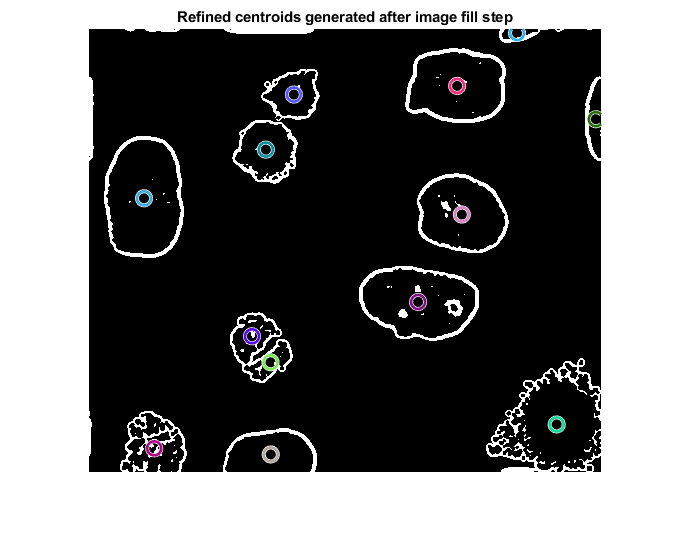

     2



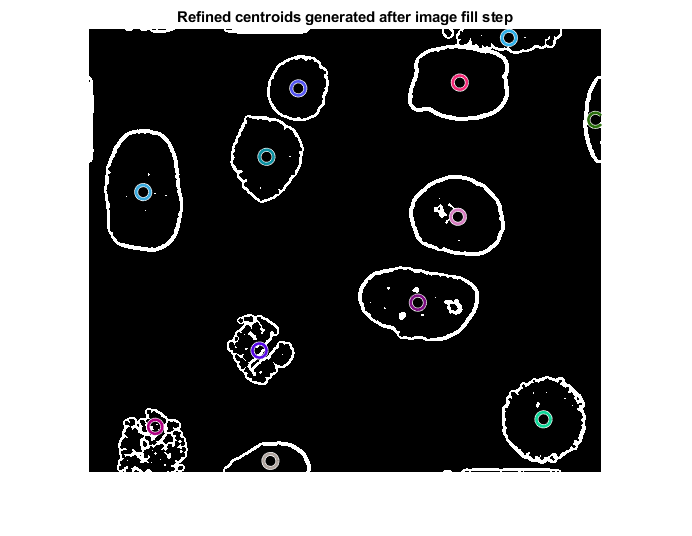

     3



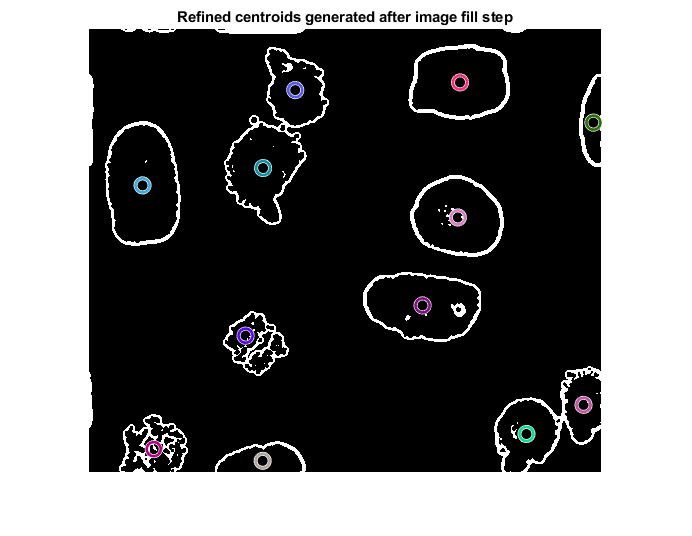

     4



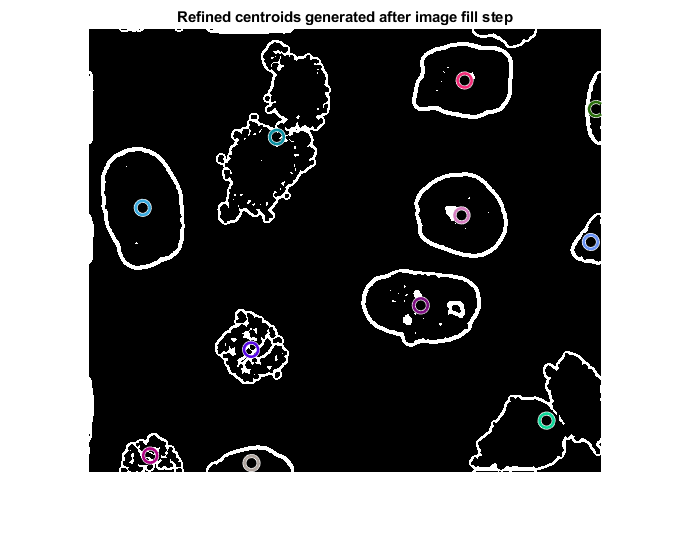

     5



Splitting event?
Splitting event?
Splitting event?


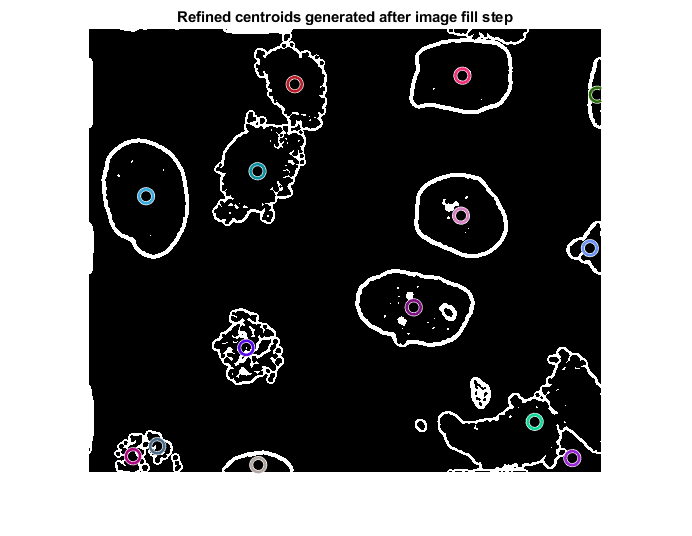

     6



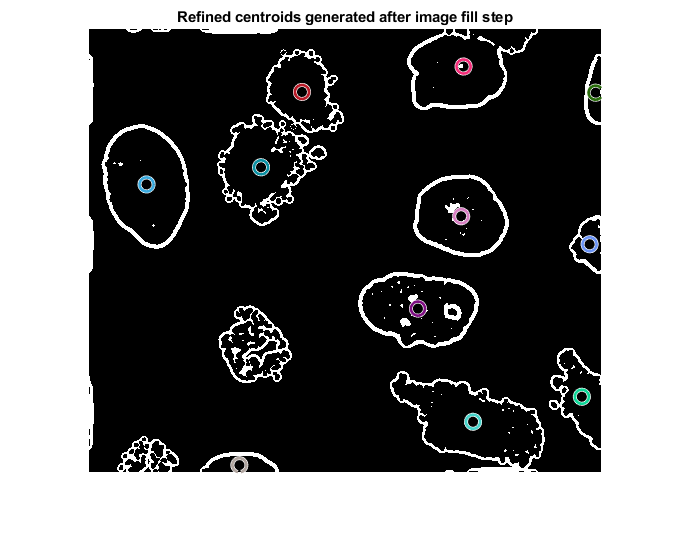

     7



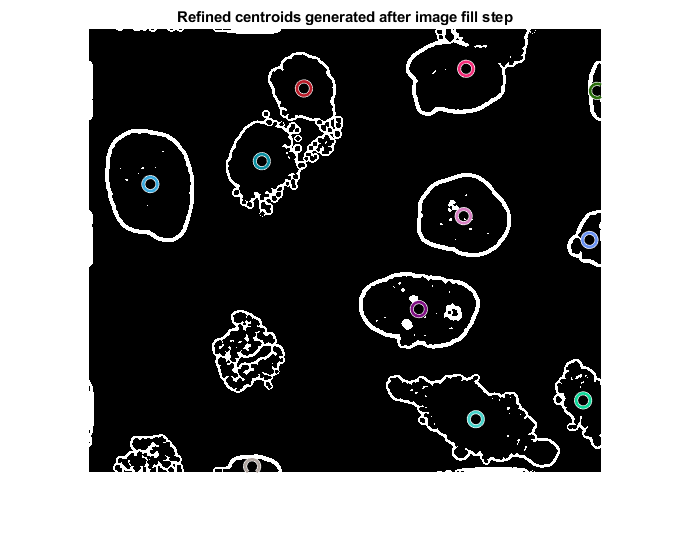

     8



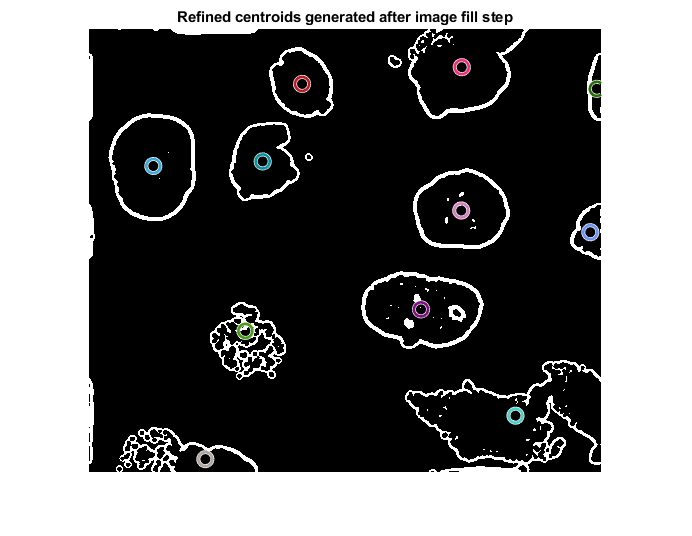

     9



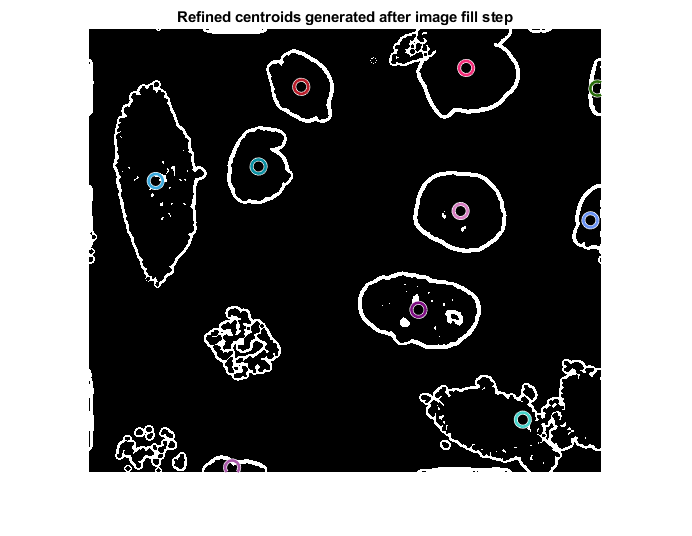

    10



Splitting event?
Splitting event?


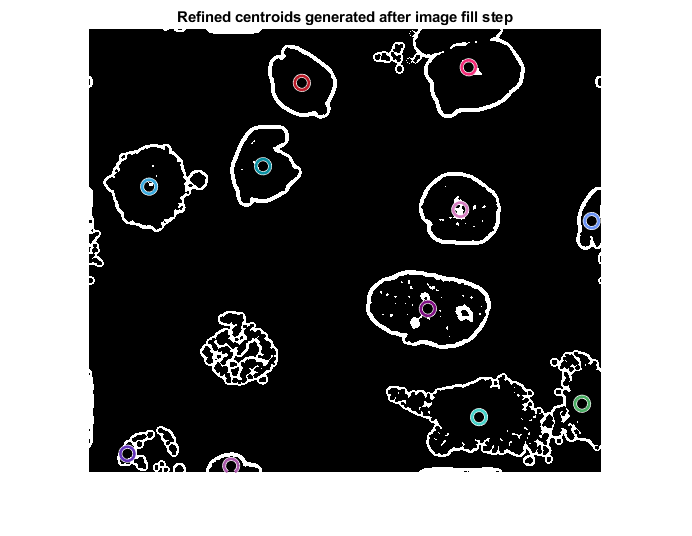

    11



Splitting event?
Splitting event?


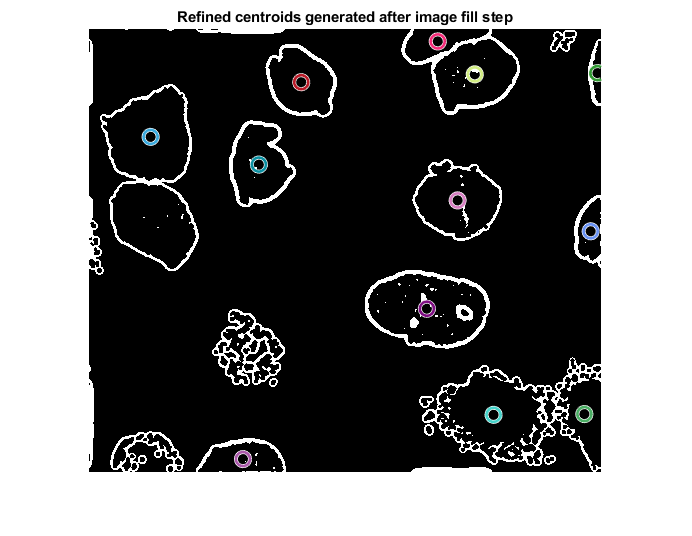

    12



Splitting event?


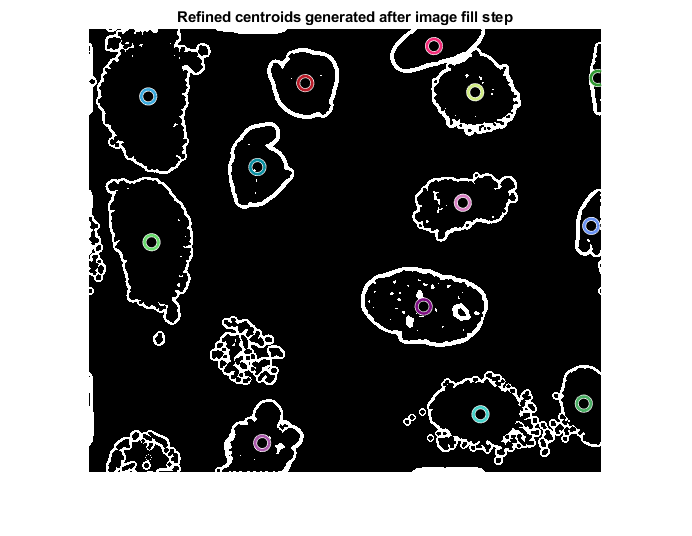

    13



Splitting event?
Splitting event?
Splitting event?


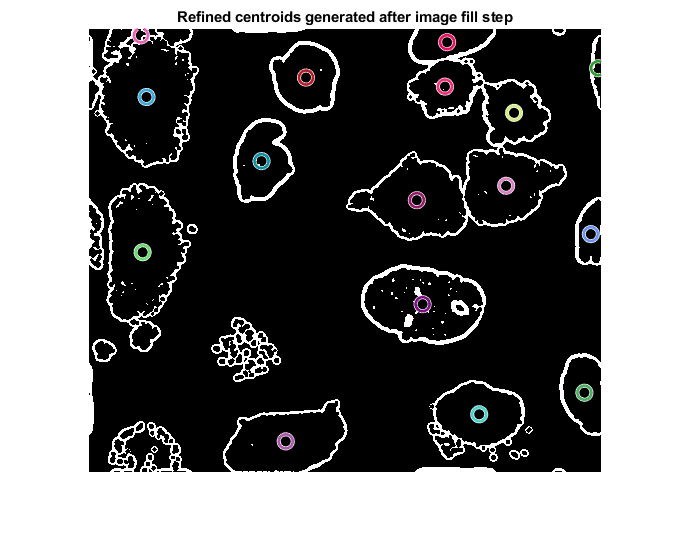

    14



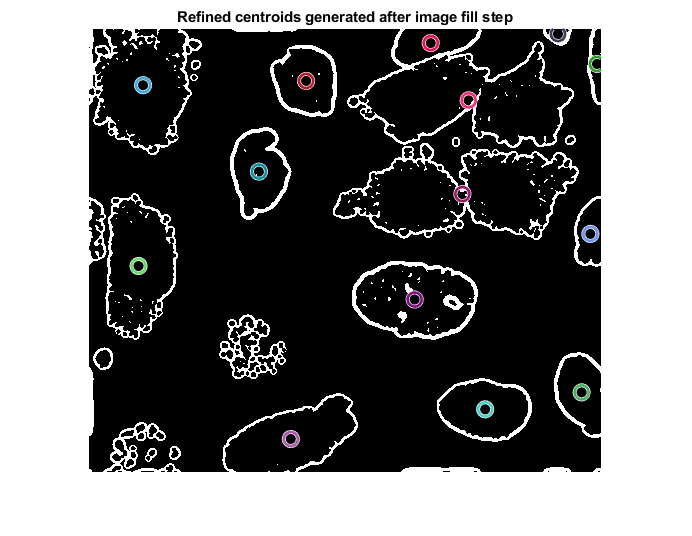

    15



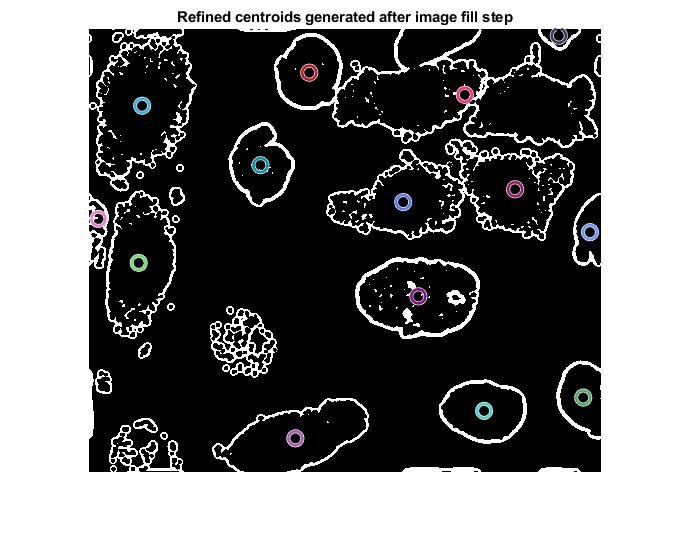

    16



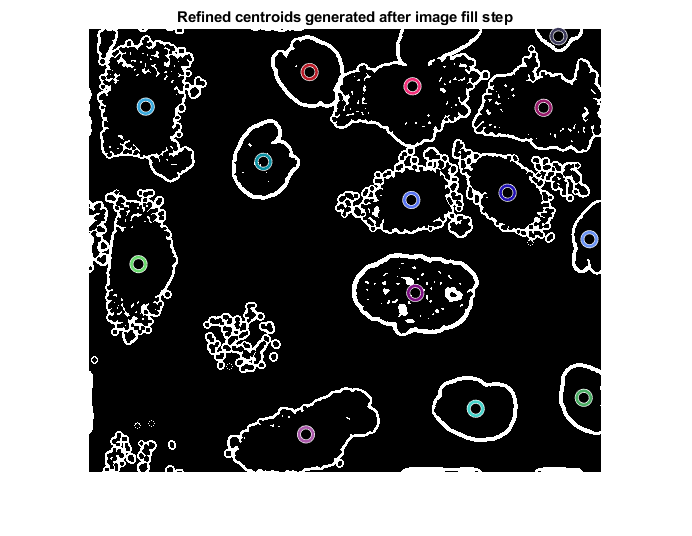

    17



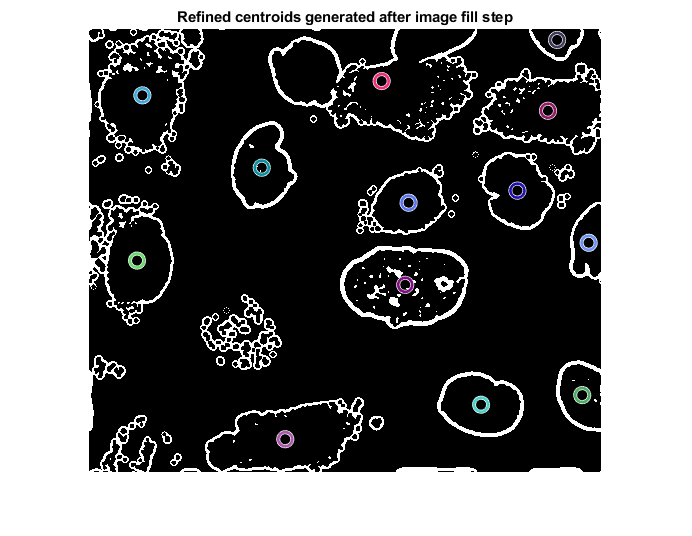

    18



Splitting event?
Splitting event?


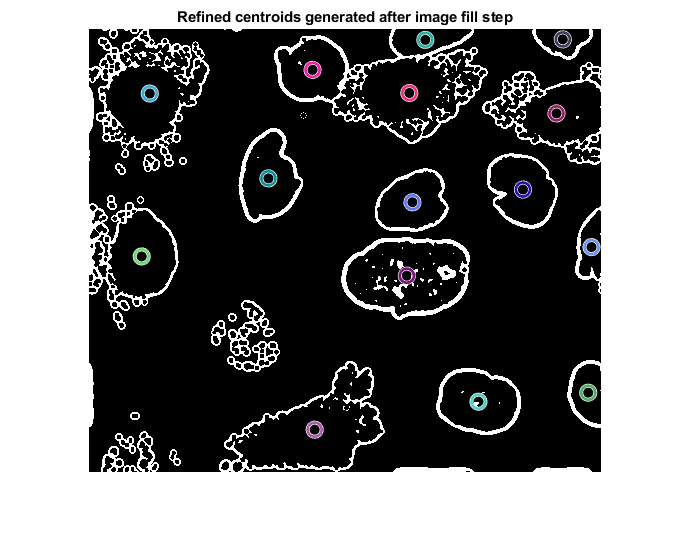

    19



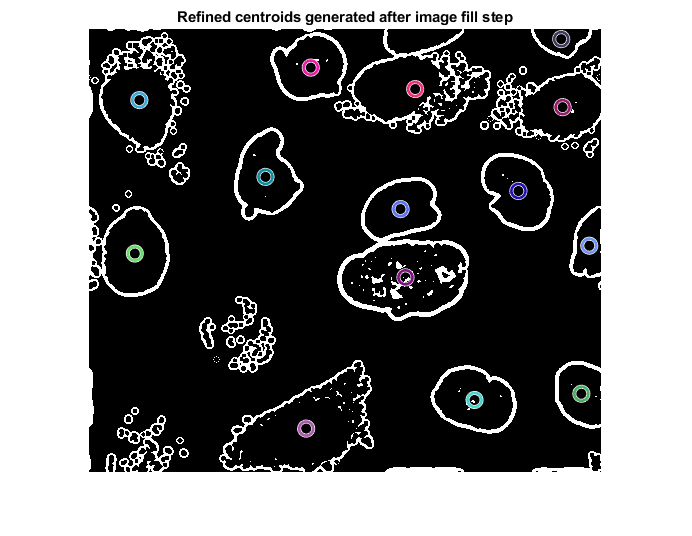

    20



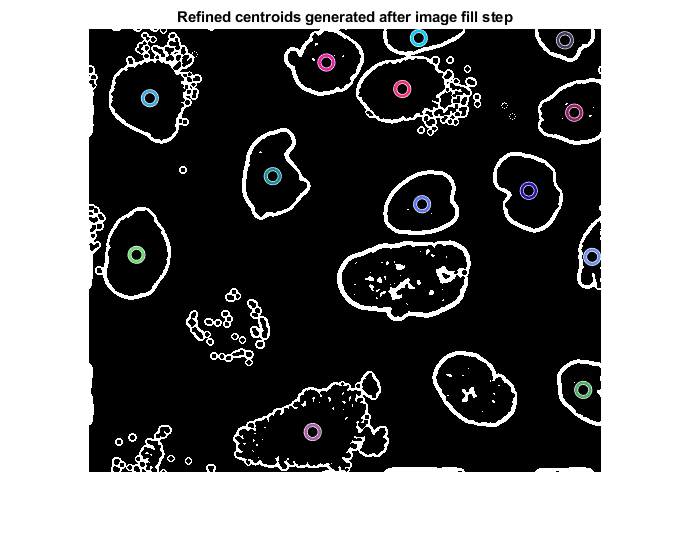

    21



Splitting event?


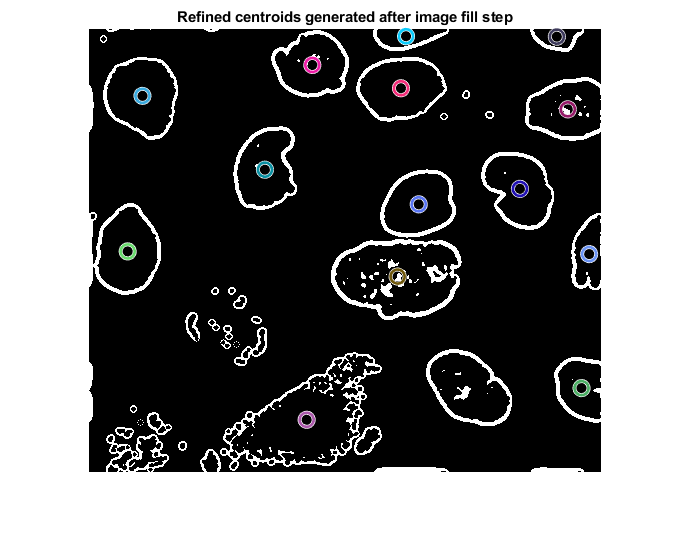

    22



Splitting event?
Splitting event?


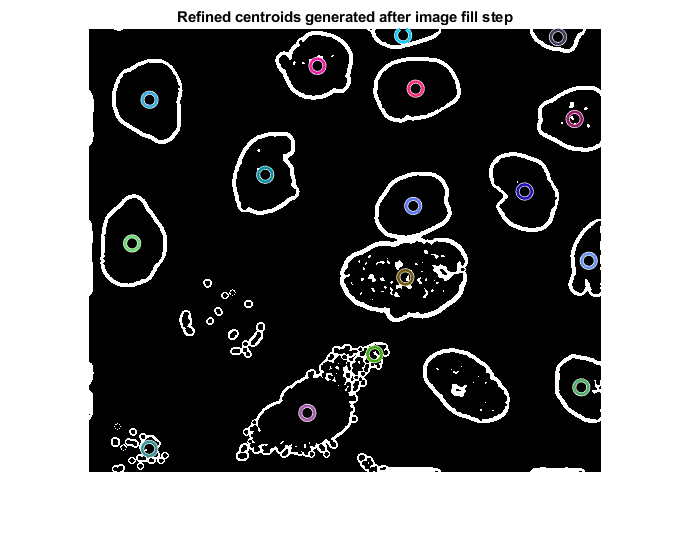

    23



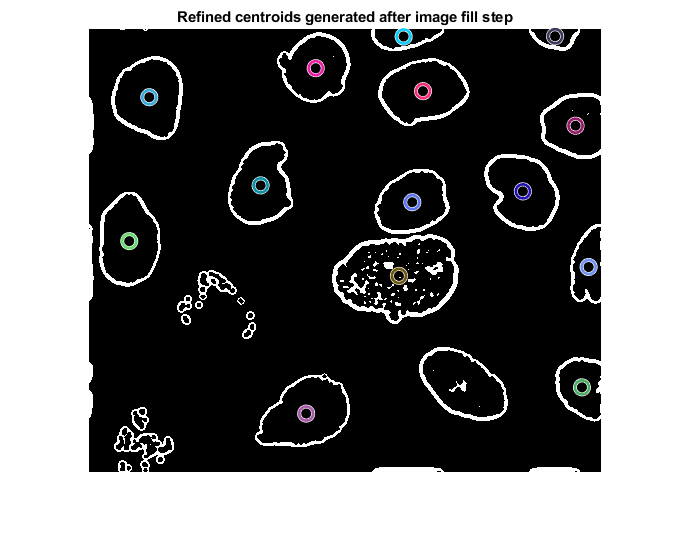

    24



Splitting event?


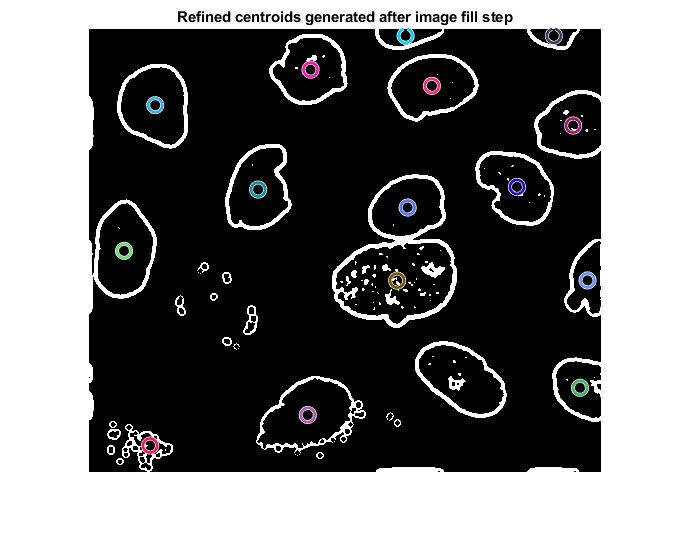

    25



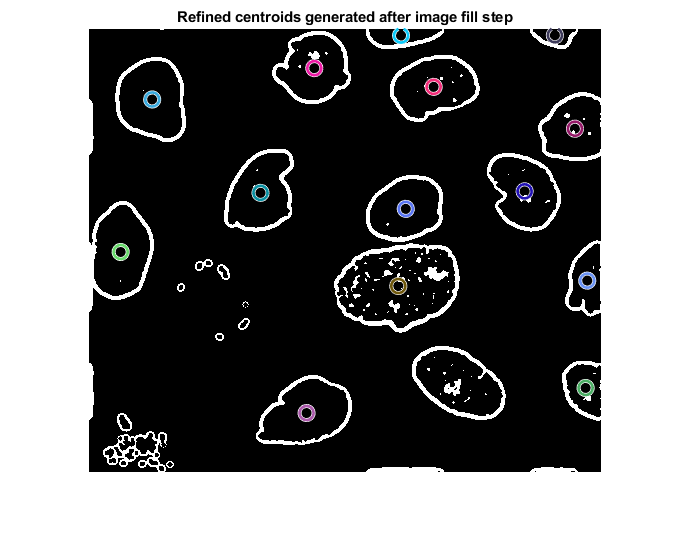

    26



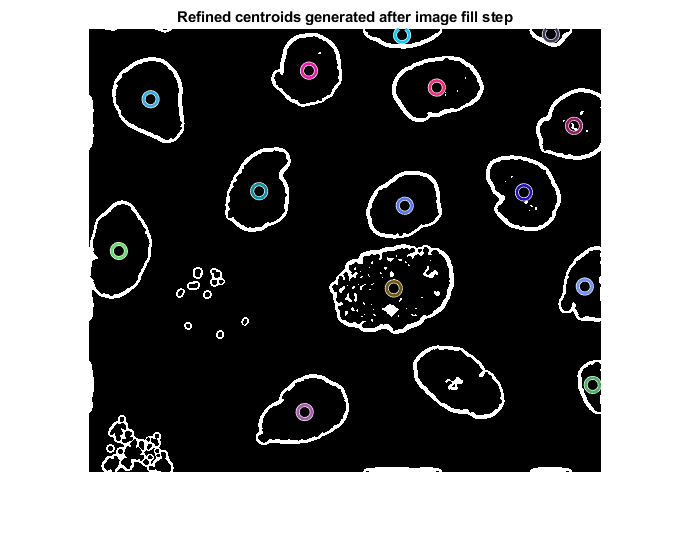

    27



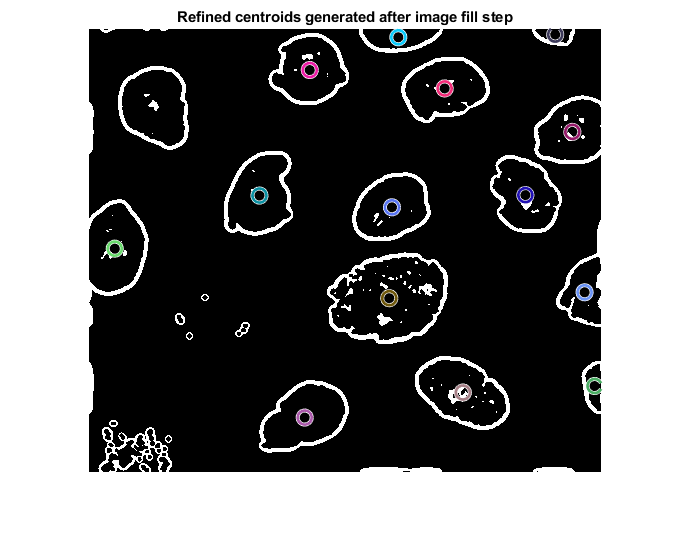

    28



Splitting event?
Splitting event?


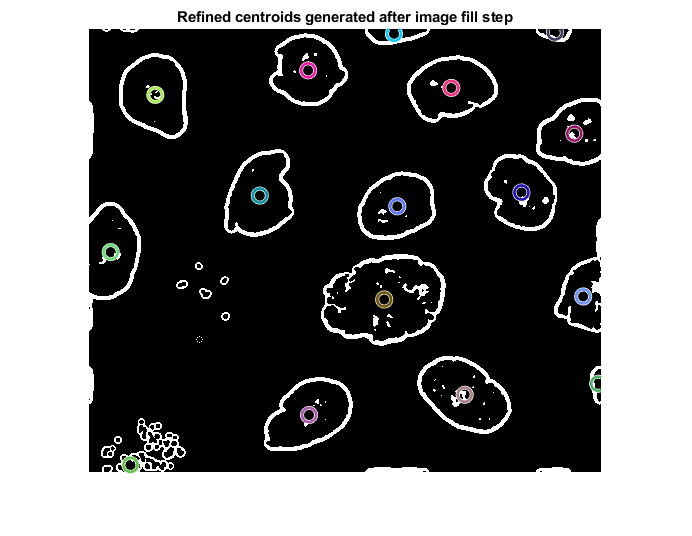

    29



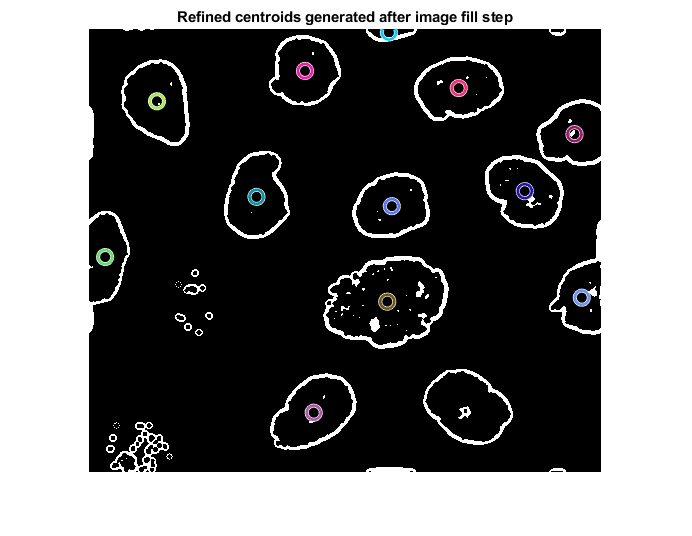

    30



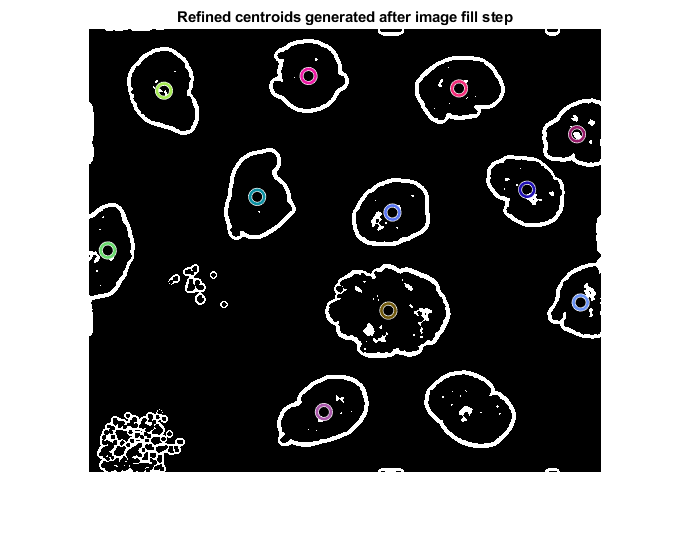

    31



Splitting event?
Splitting event?


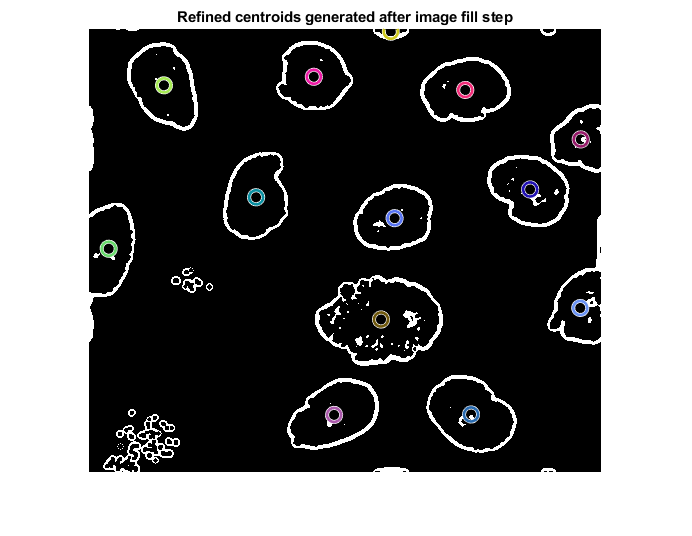

    32



Splitting event?
Splitting event?


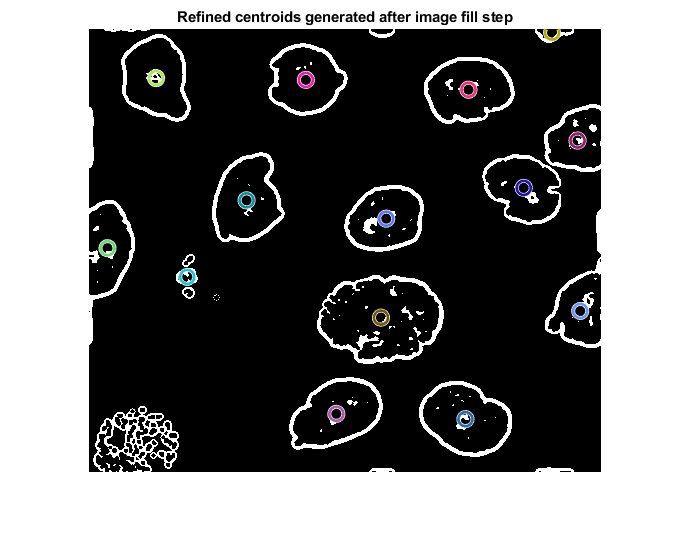

    33



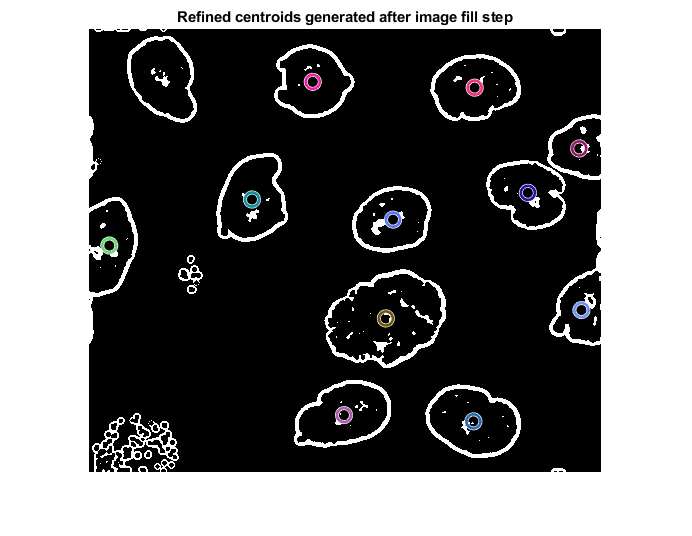

    34



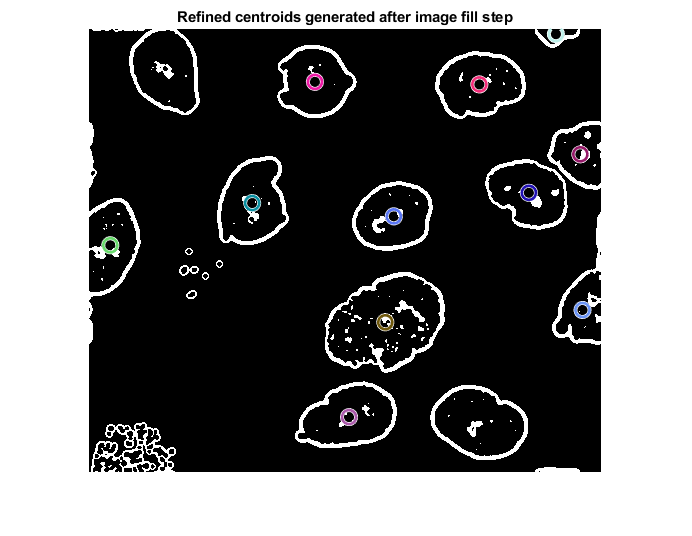

    35



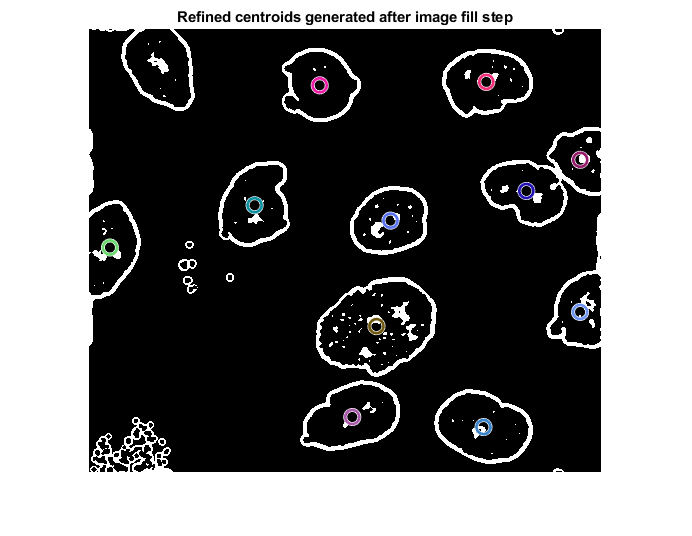

    36



Splitting event?
Splitting event?


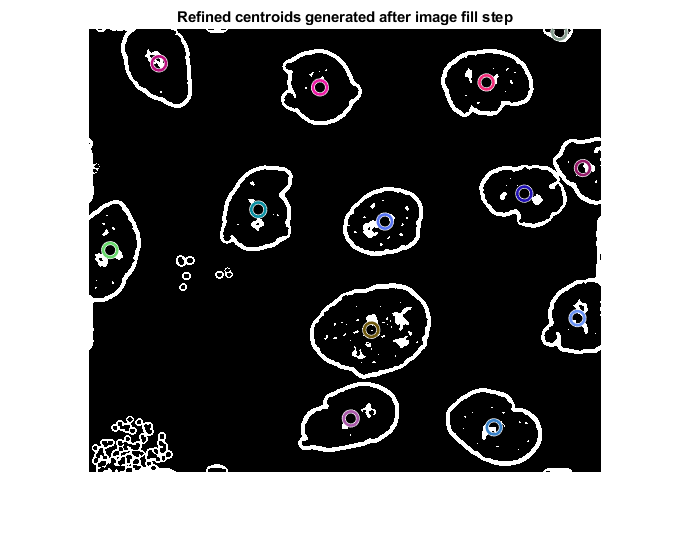

    37



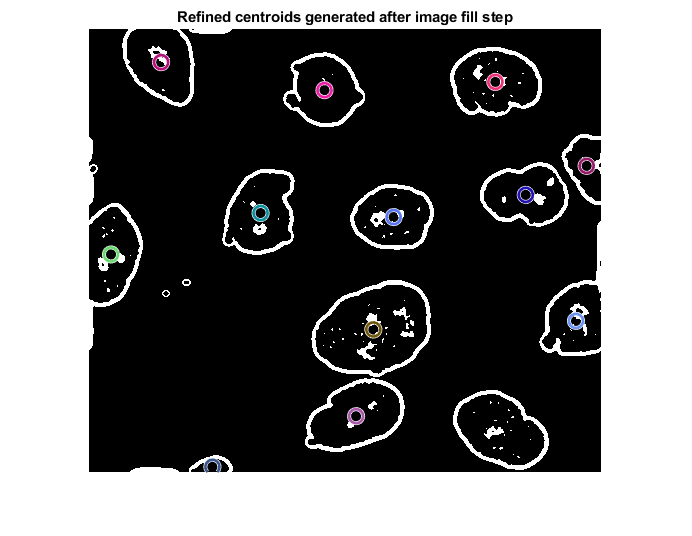

    38



Splitting event?


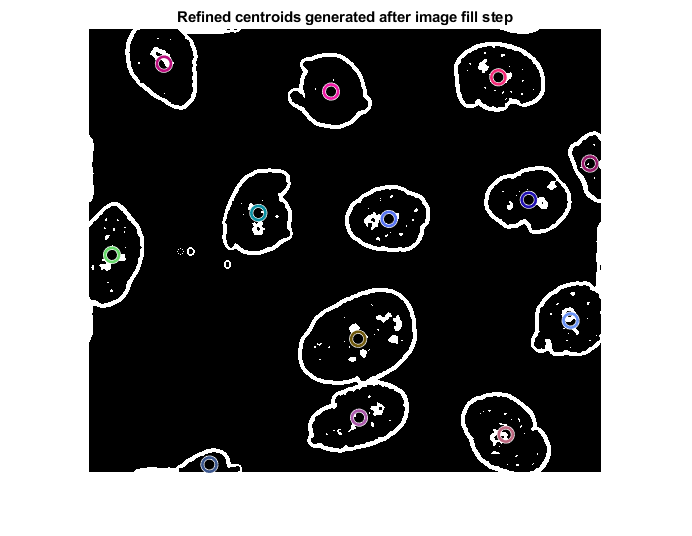

    39



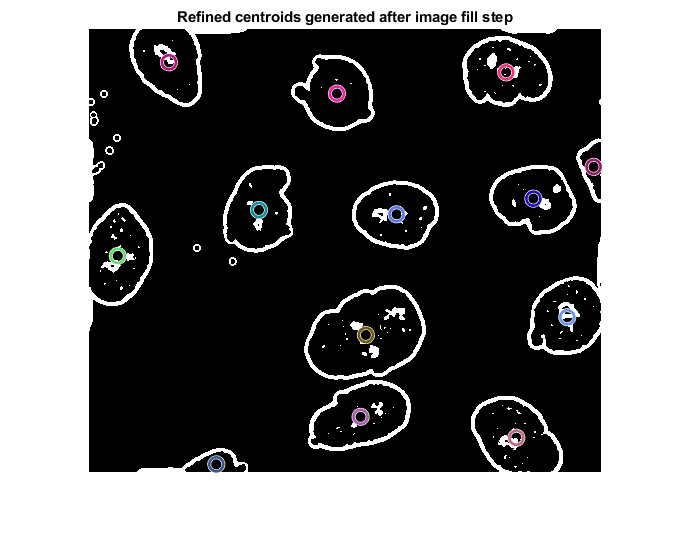

    40



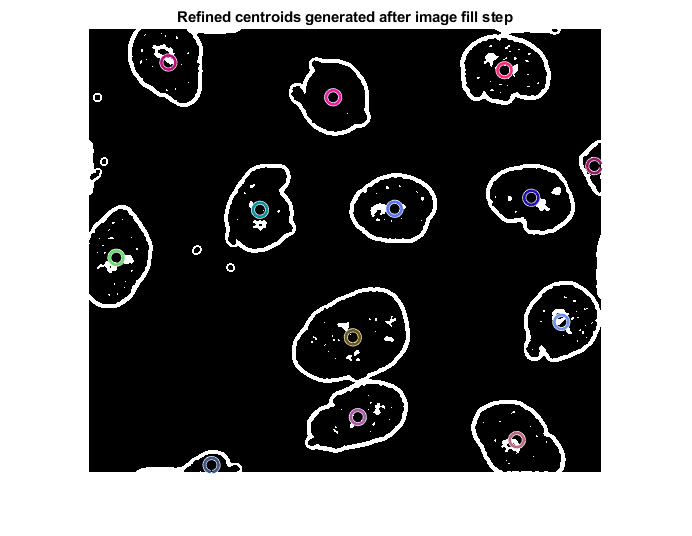

    41



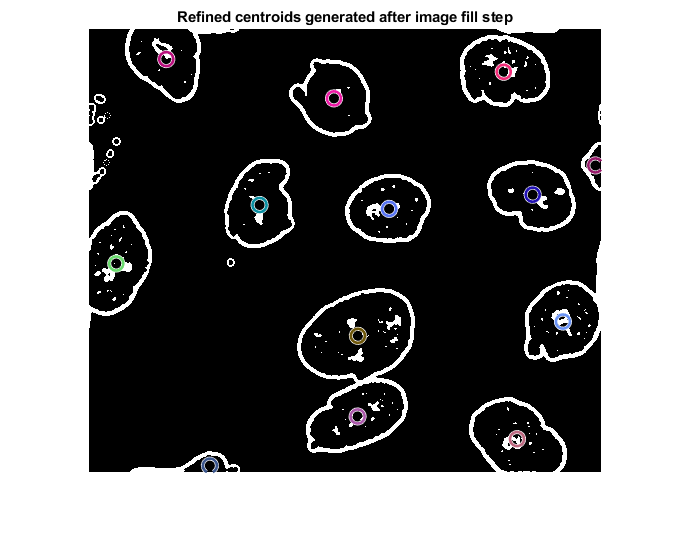

    42



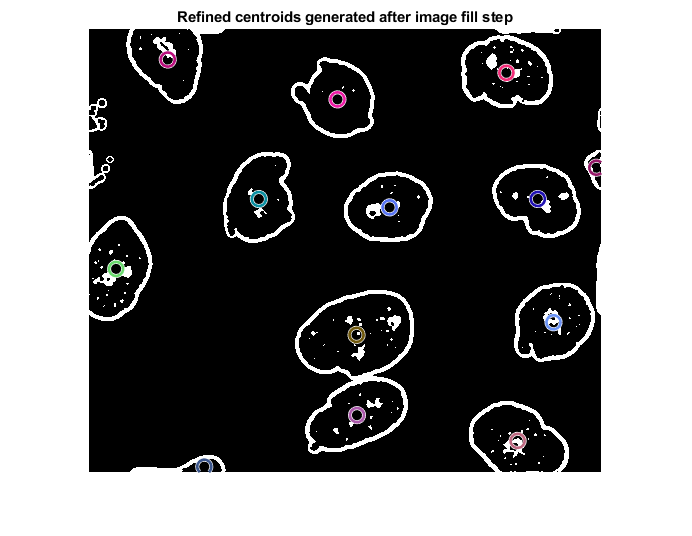

    43



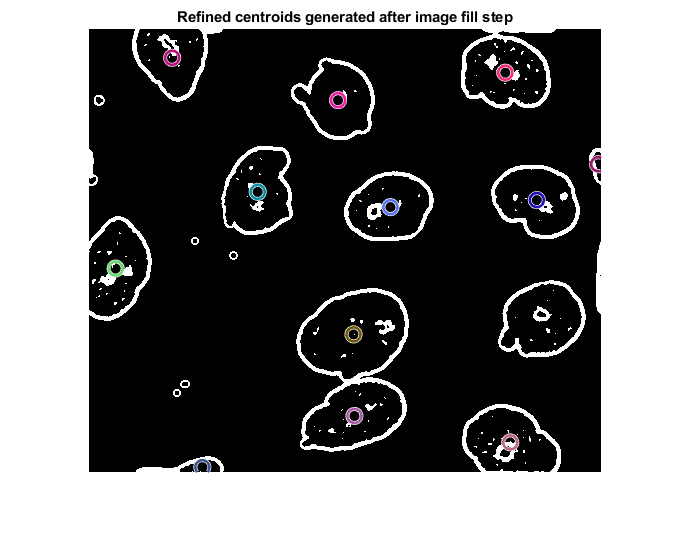

    44



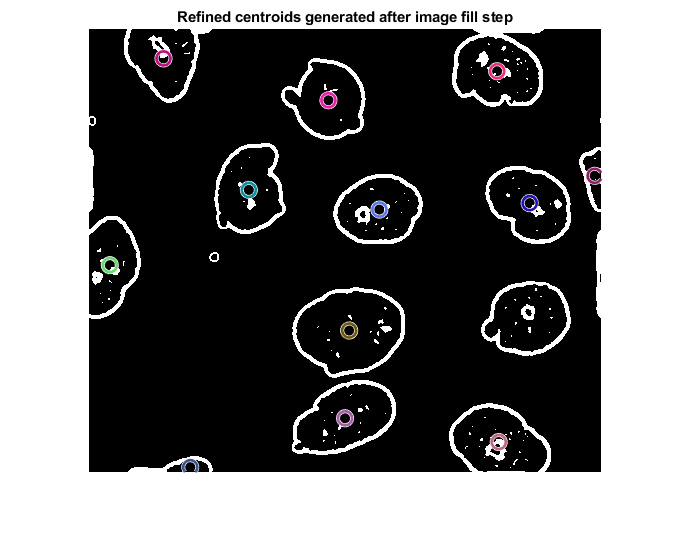

    45



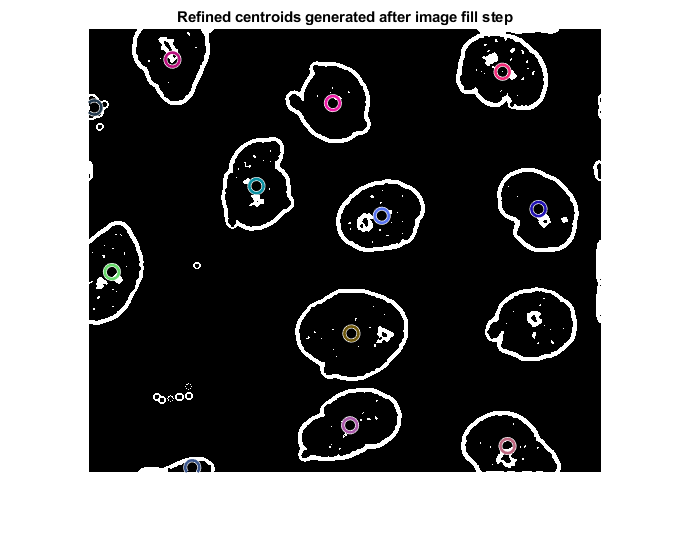

    46



Splitting event?
Splitting event?


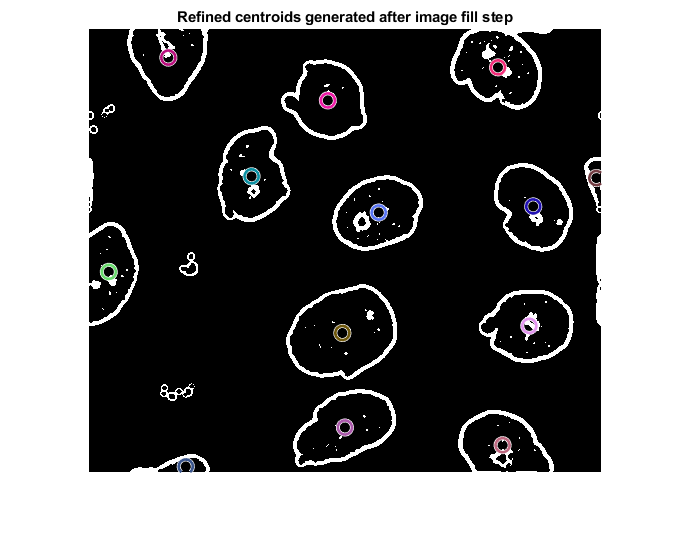

    47



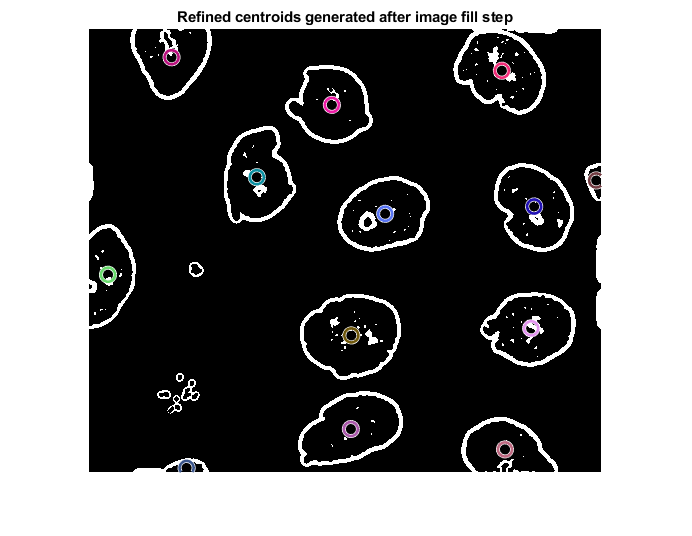

    48



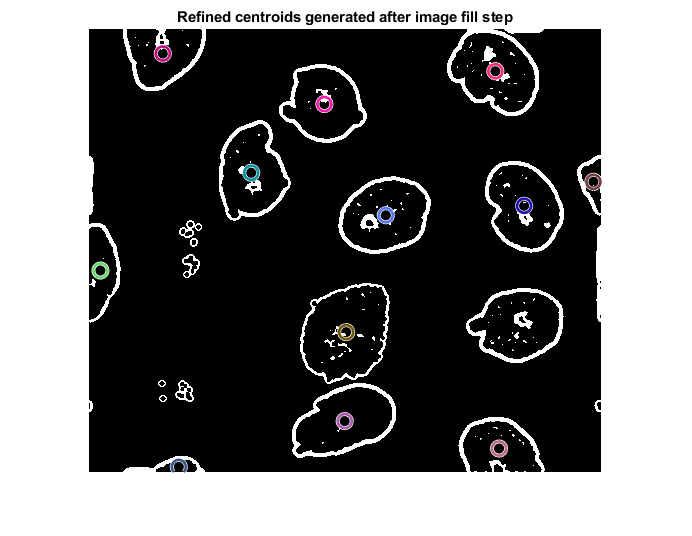

    49



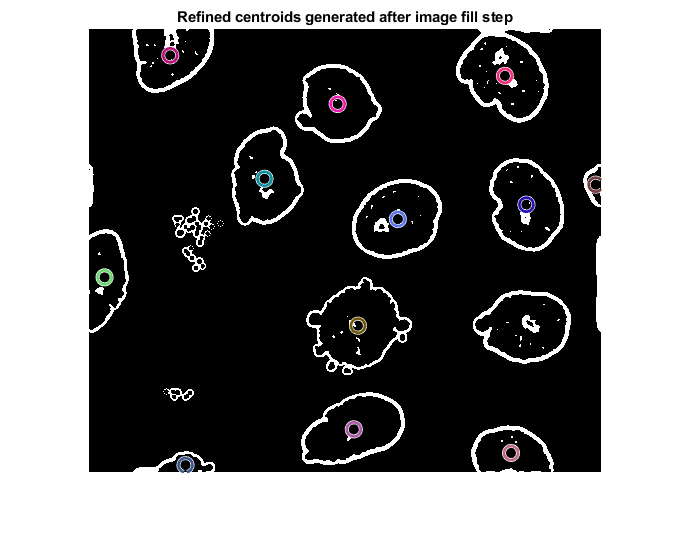

    50



Splitting event?


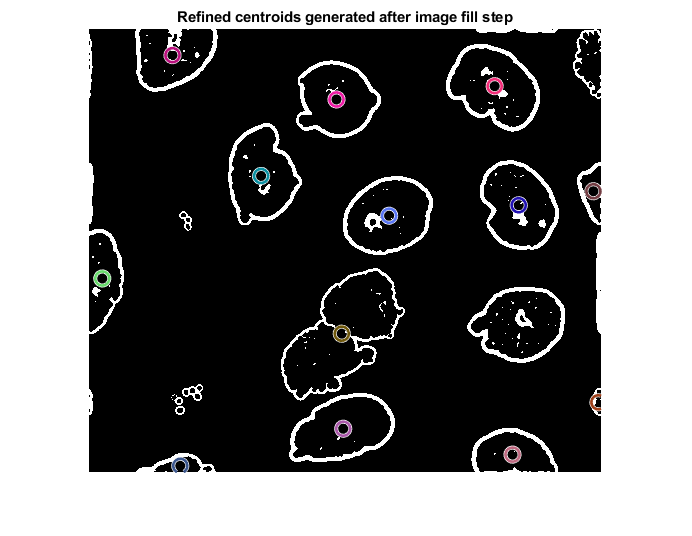

    51



Splitting event?


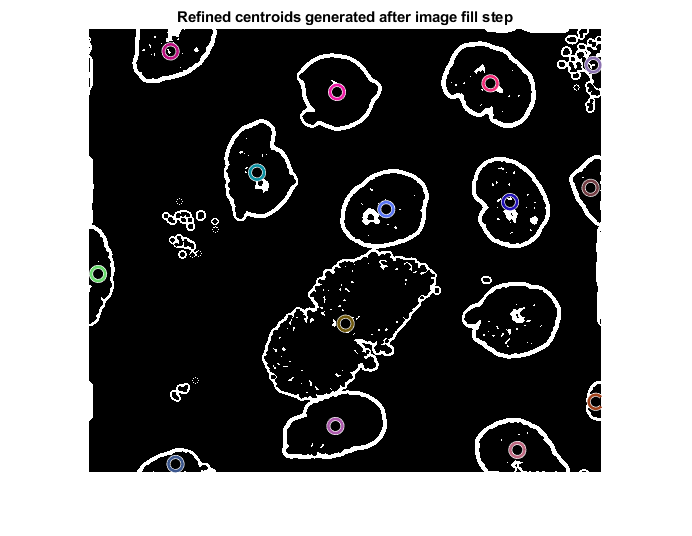

    52



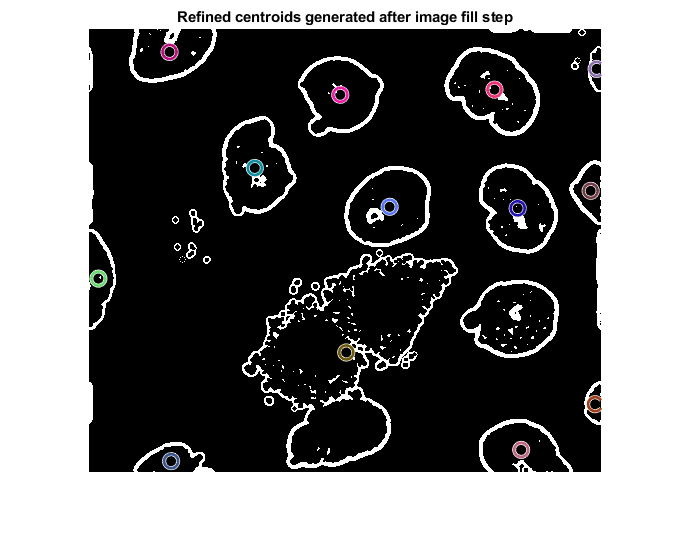

    53



Splitting event?


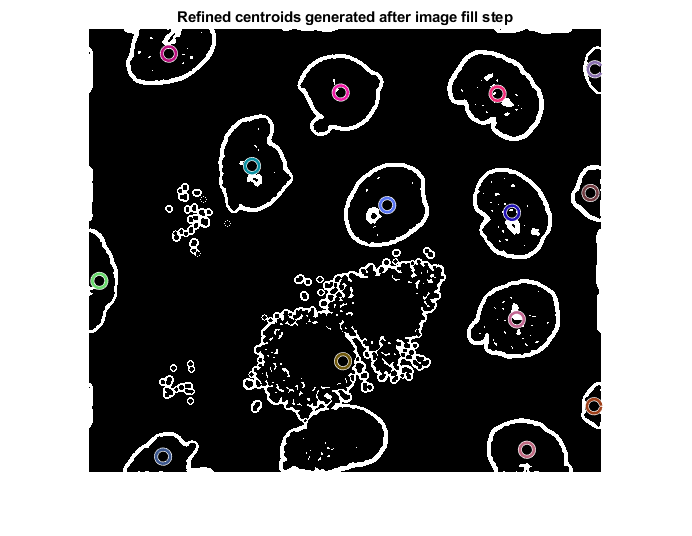

    54



Splitting event?
Splitting event?


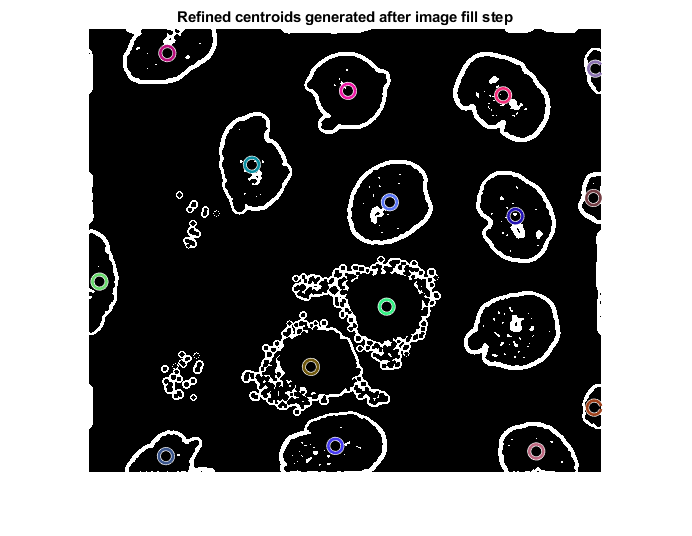

    55



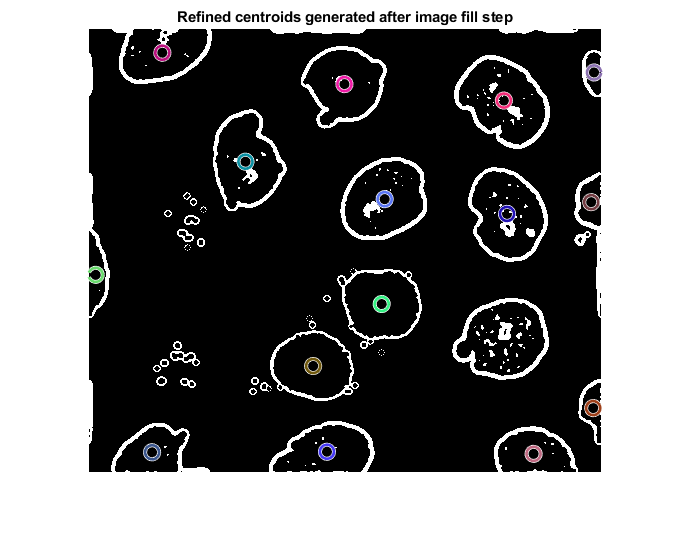

    56



Splitting event?


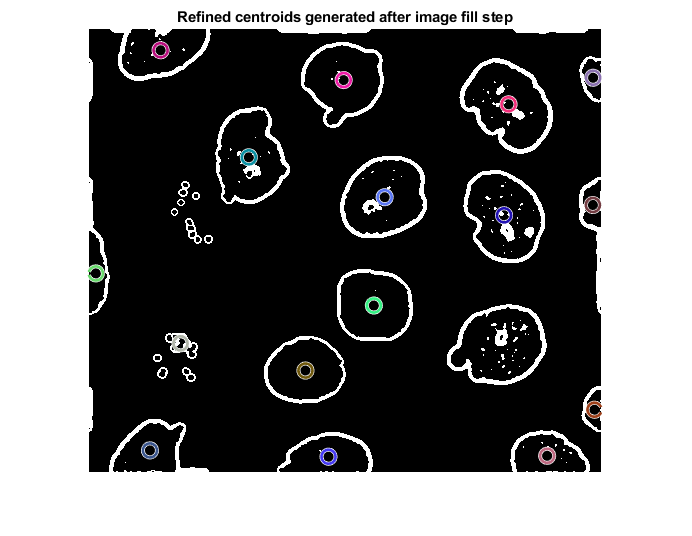

    57



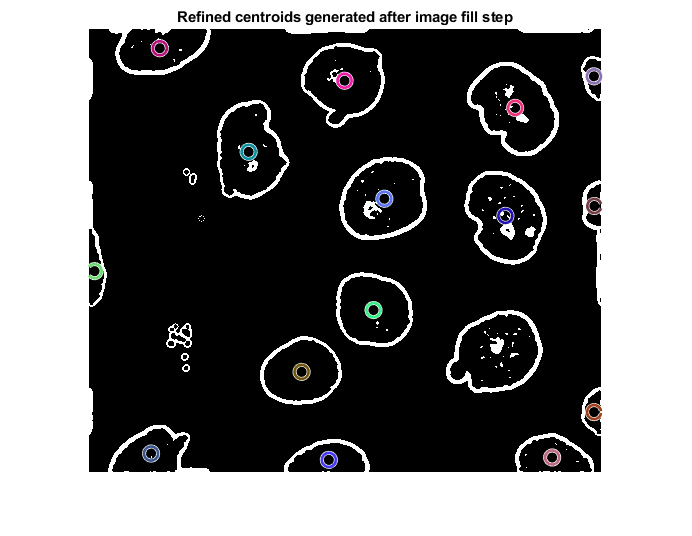

    58



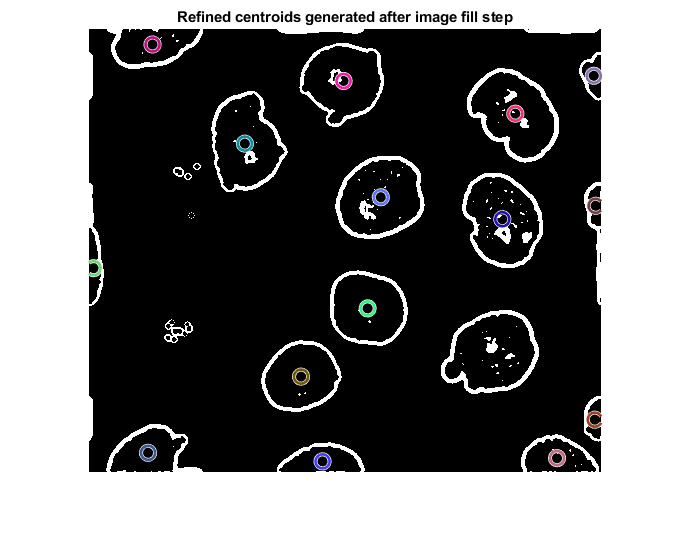

    59



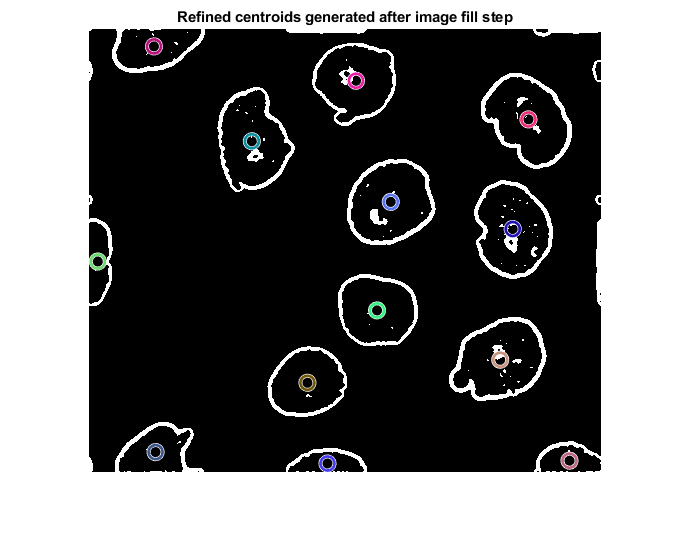

    60



Splitting event?
Splitting event?


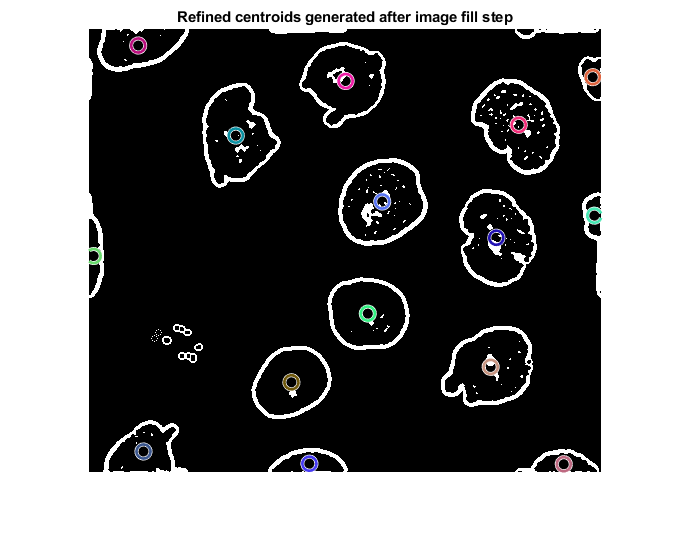

    61



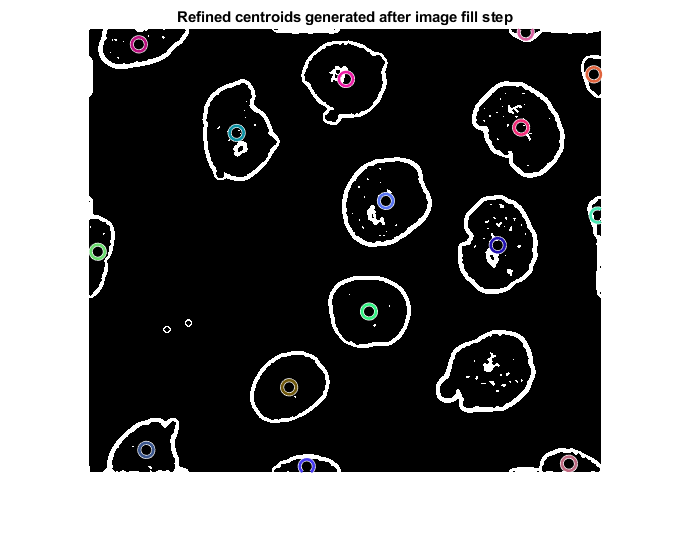

    62



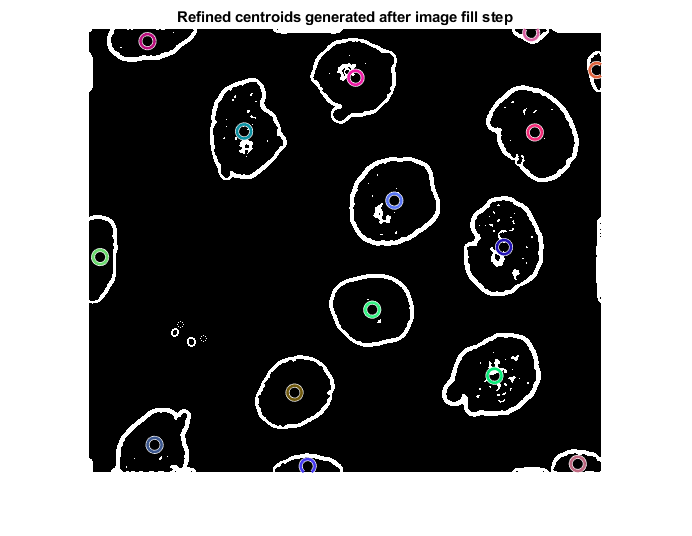

    63



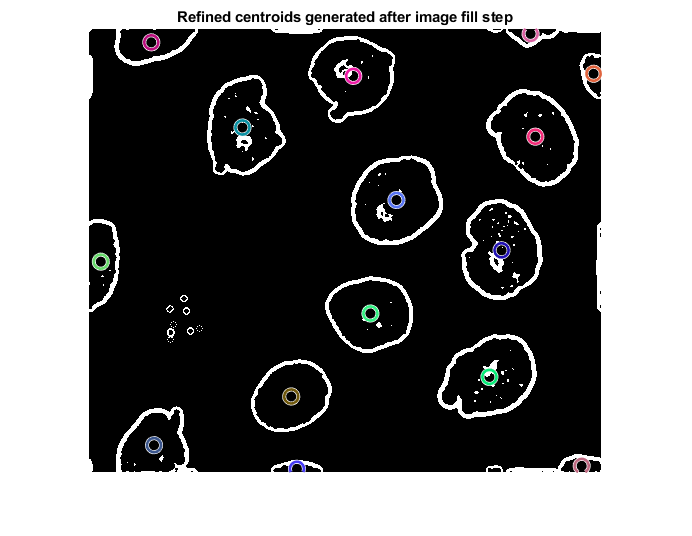

    64



Splitting event?
Splitting event?
Splitting event?


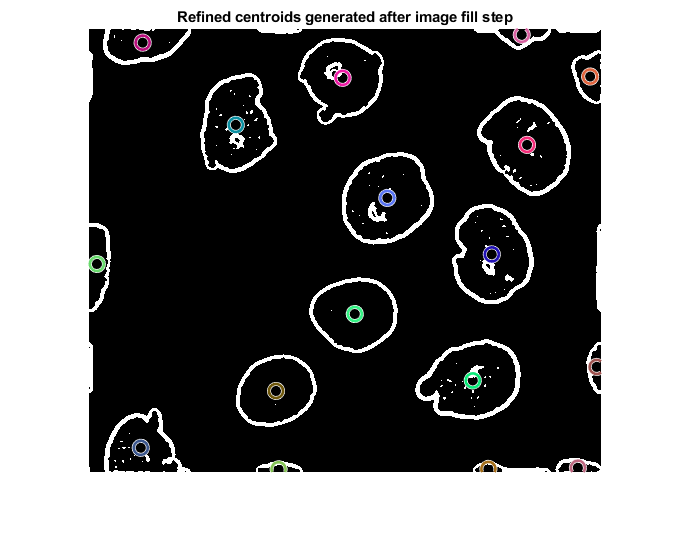

    65



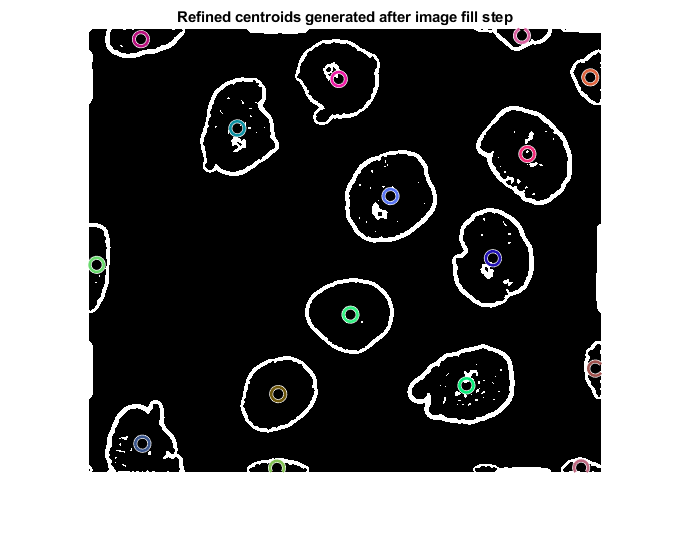

    66



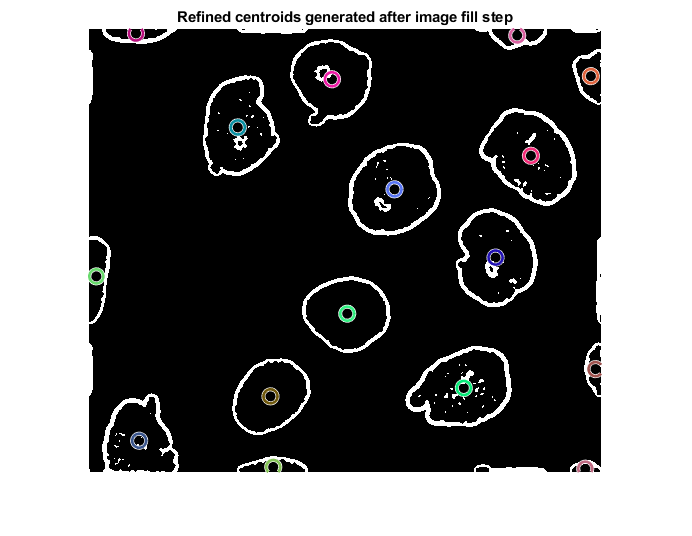

    67



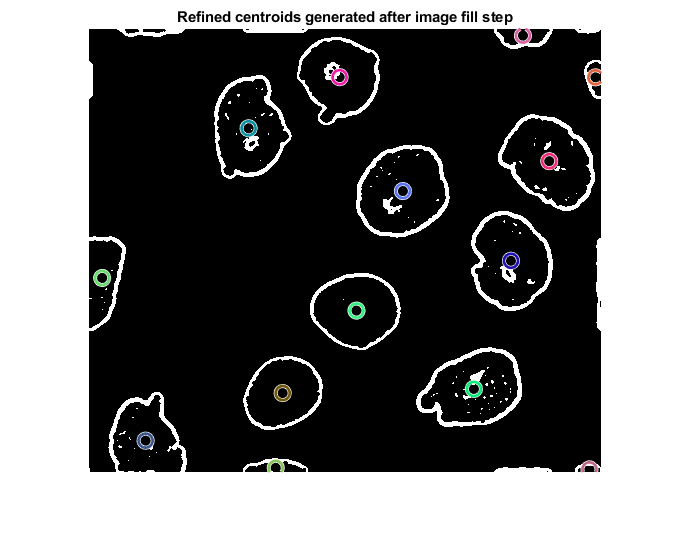

    68



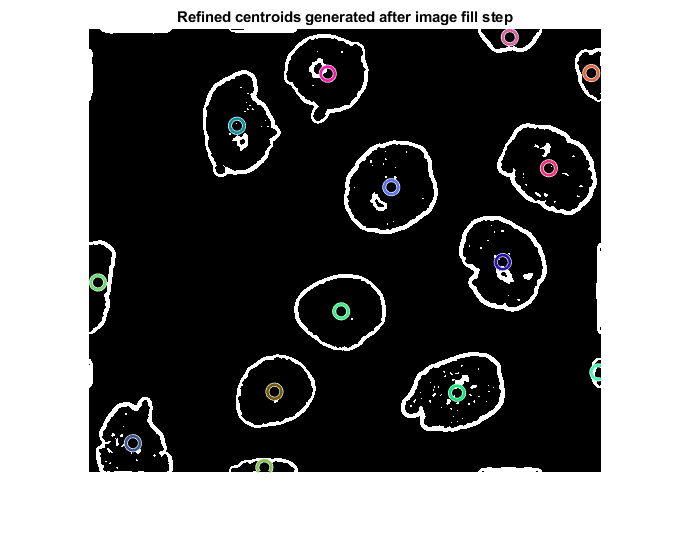

    69



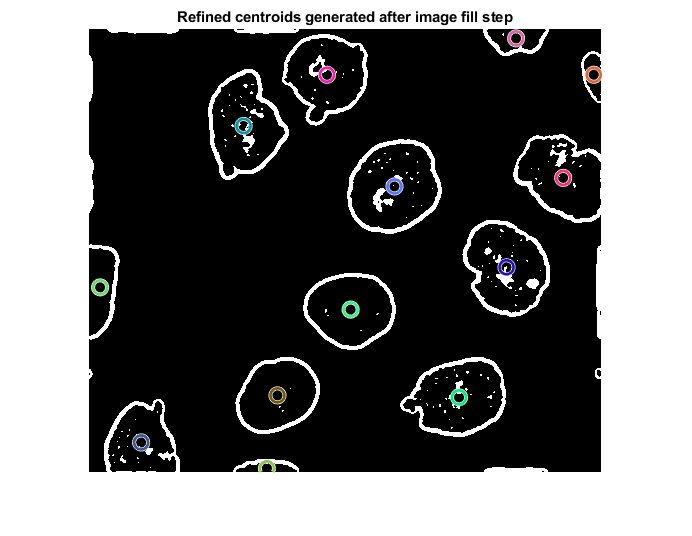

    70



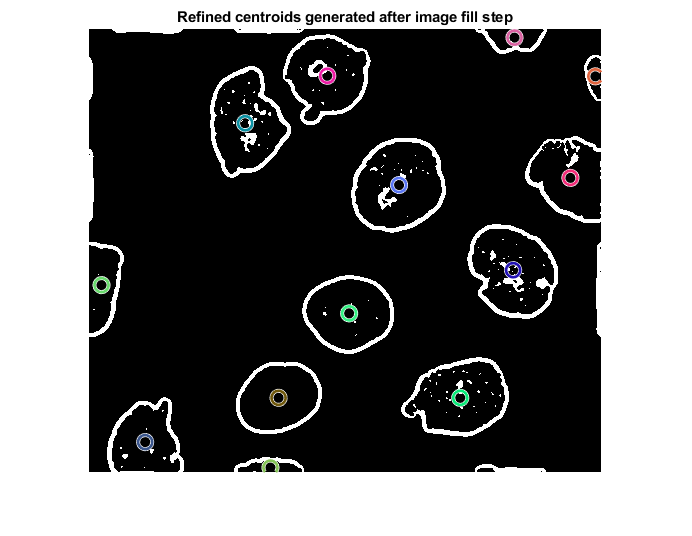

    71



Splitting event?


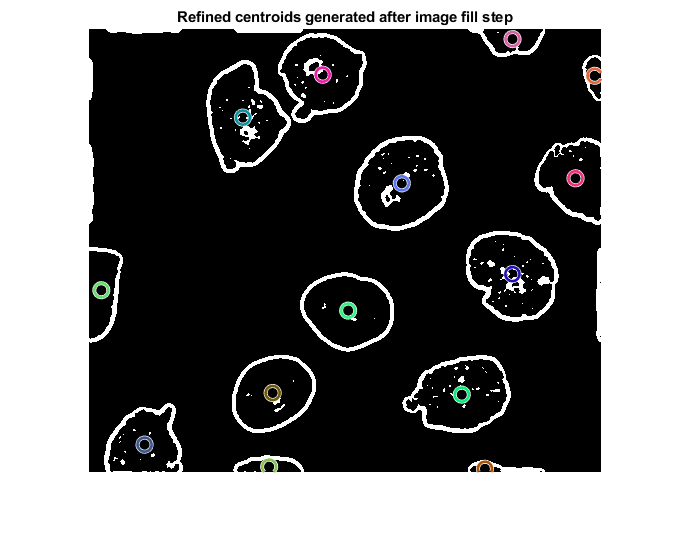

    72



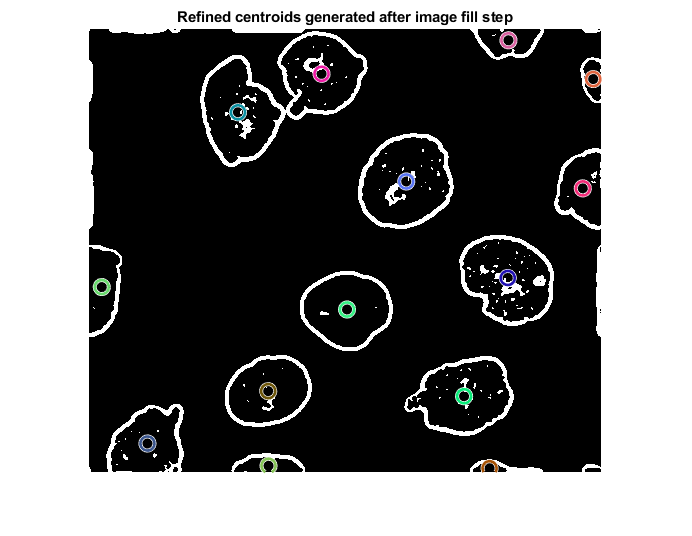

    73



Splitting event?


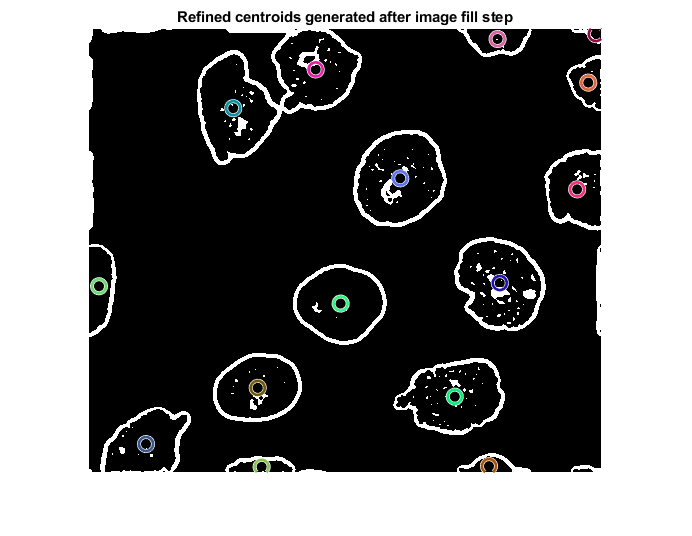

    74



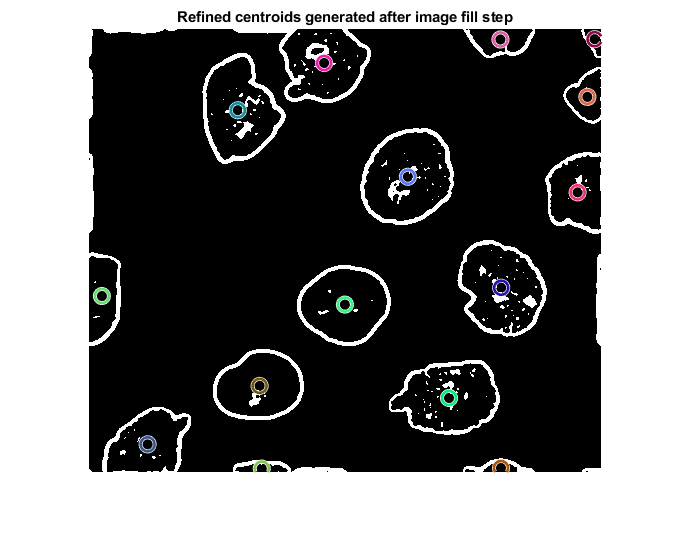

    75



Splitting event?


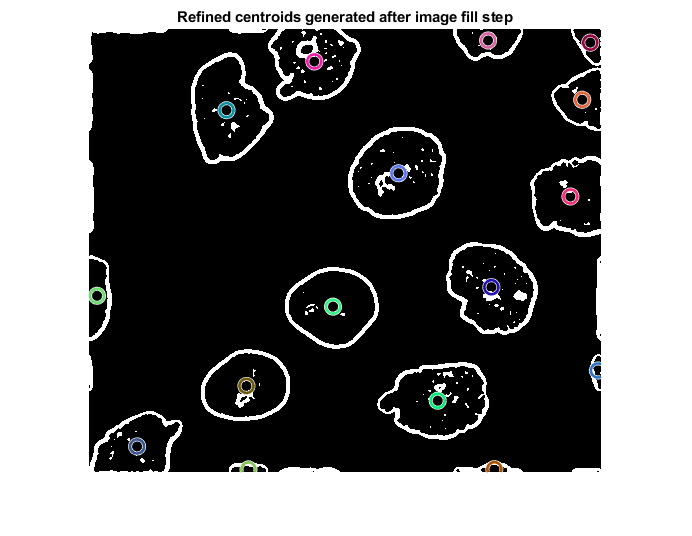

    76



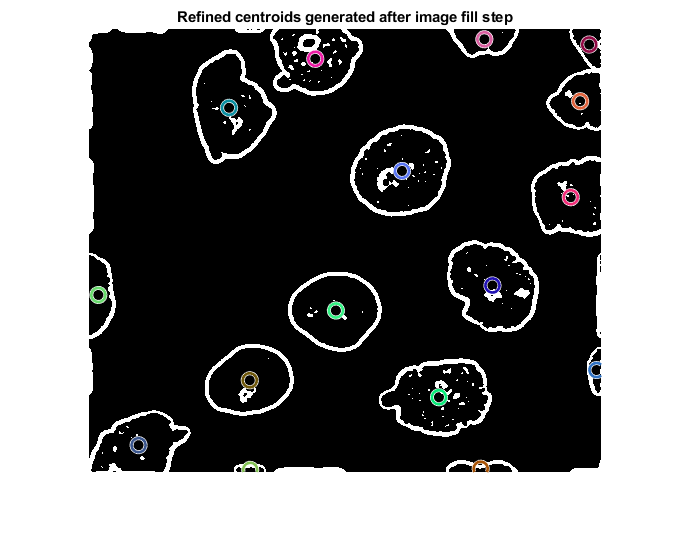

    77



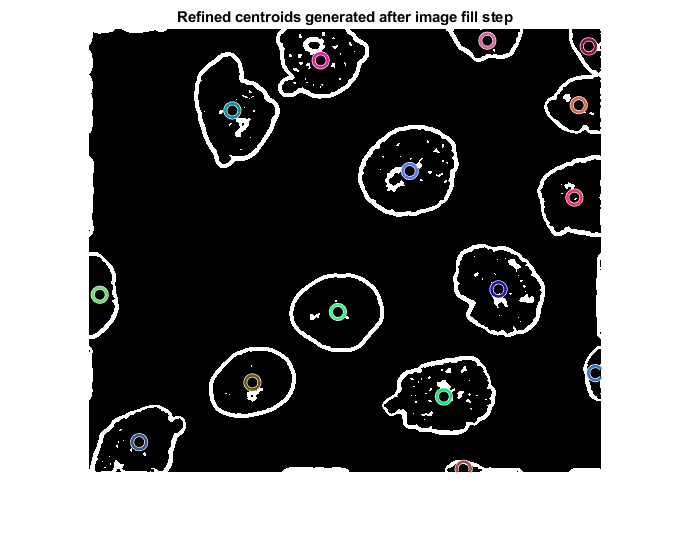

    78



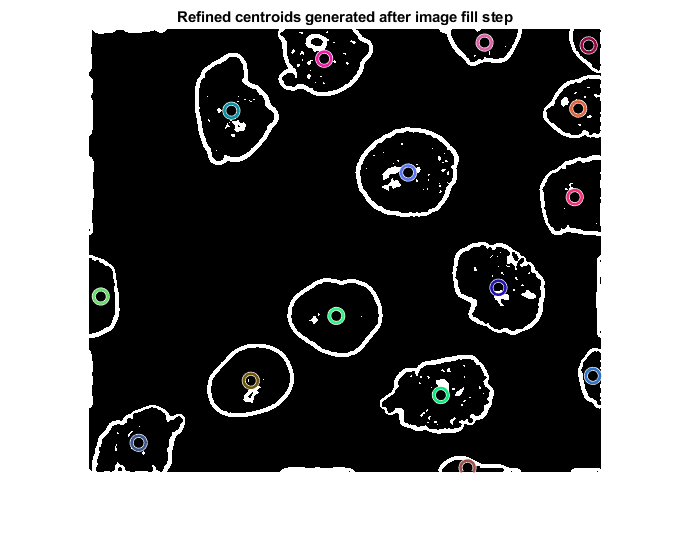

    79



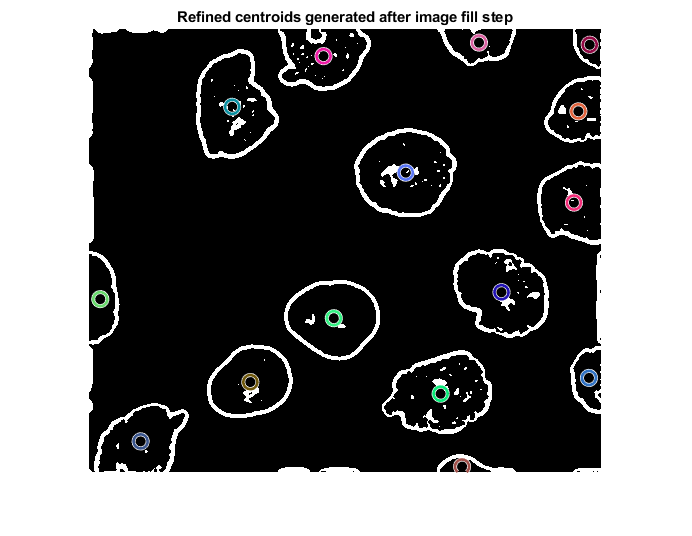

    80



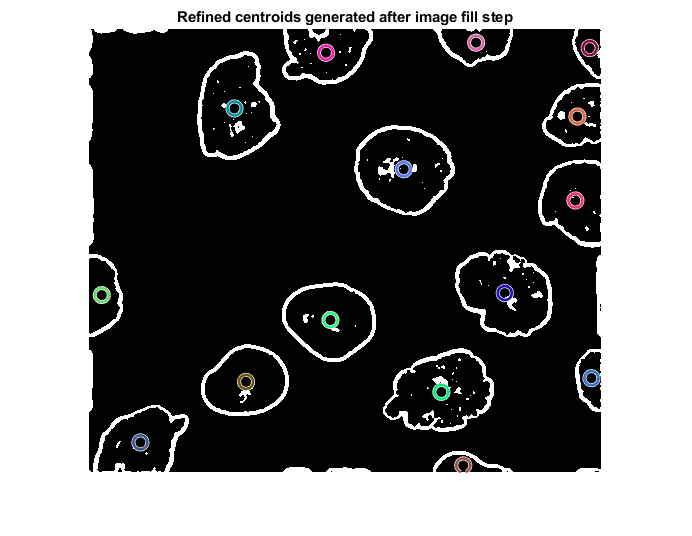

    81



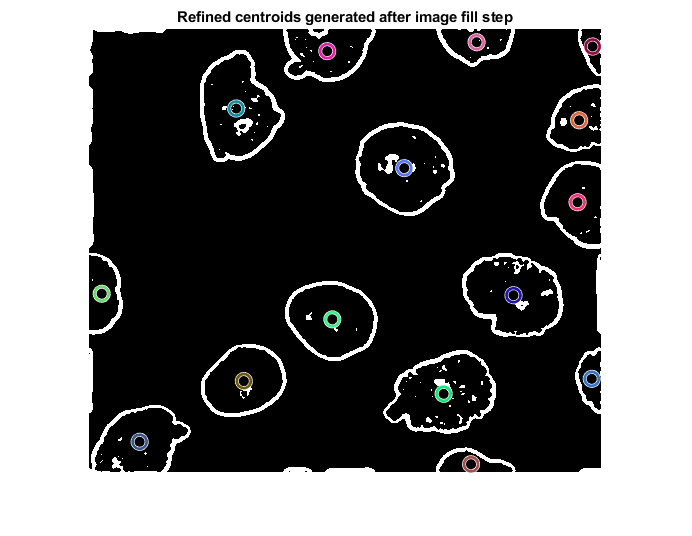

    82



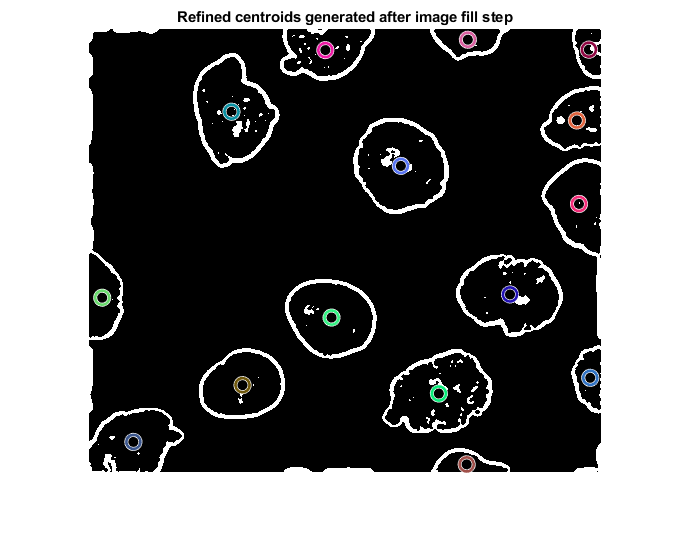

    83



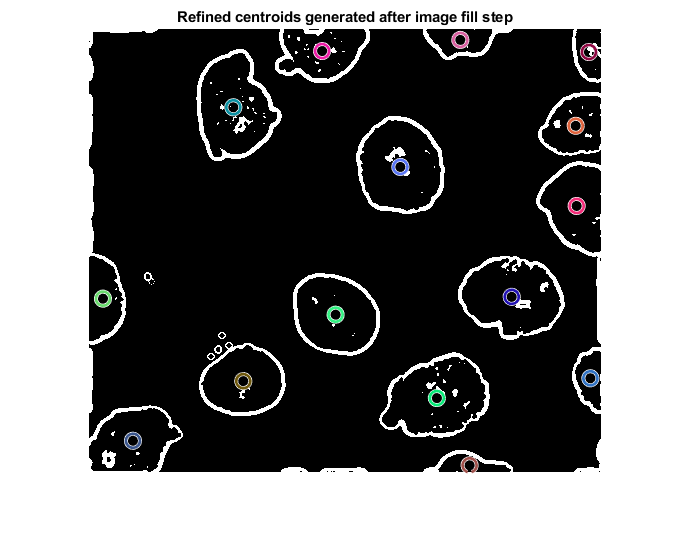

    84



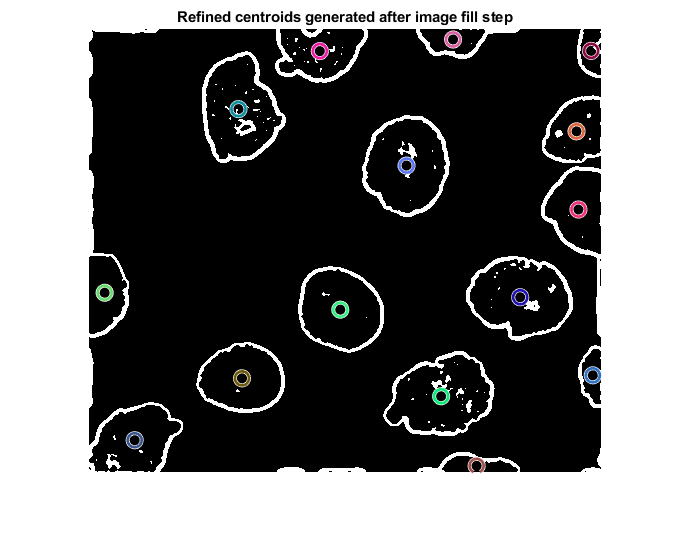

    85



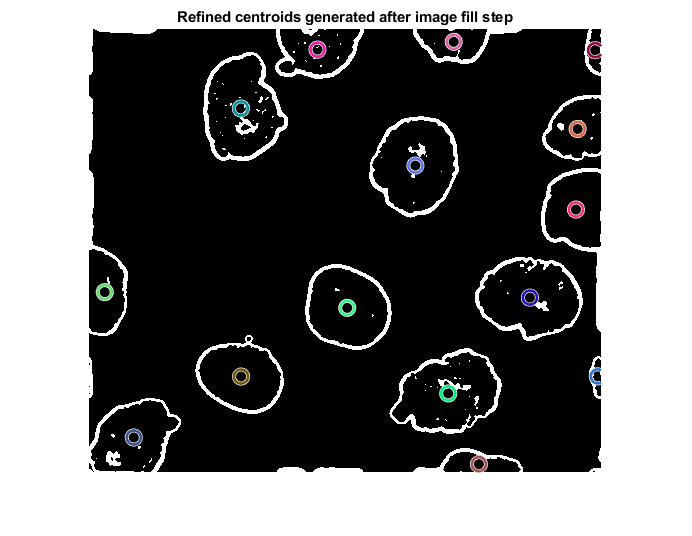

    86



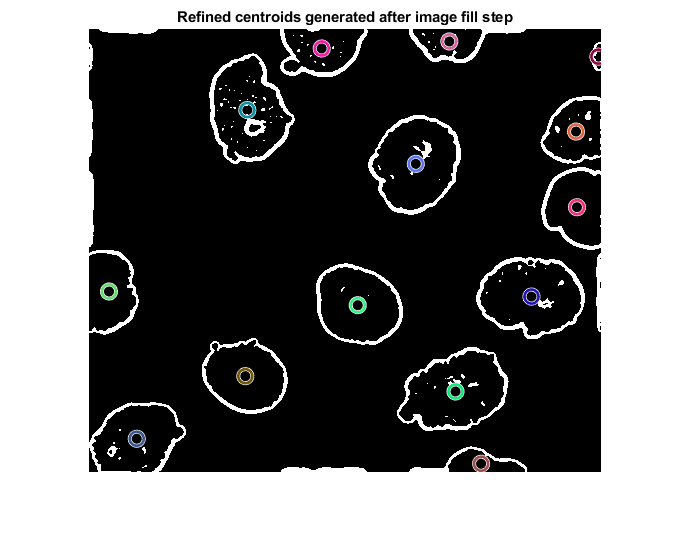

    87



Splitting event?


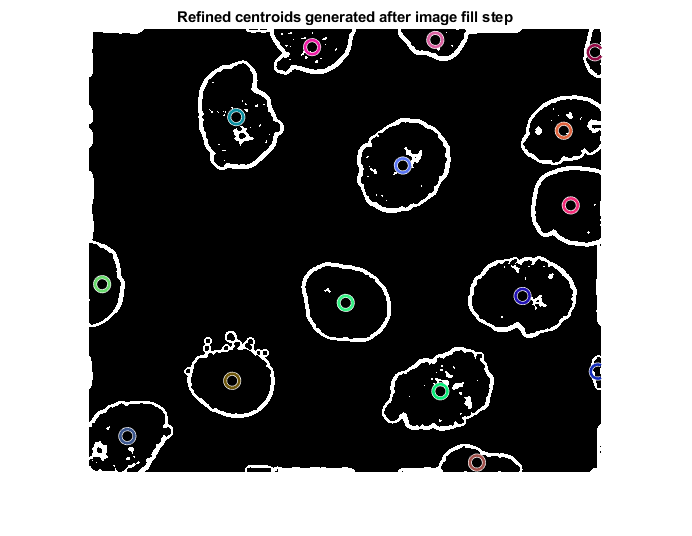

    88



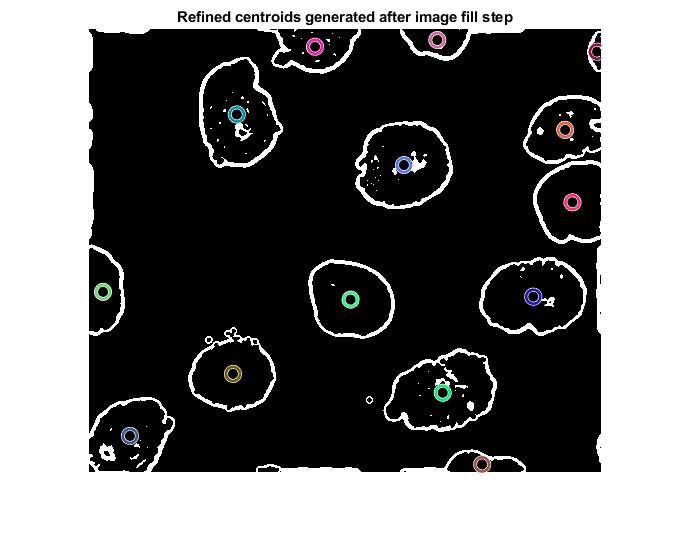

    89



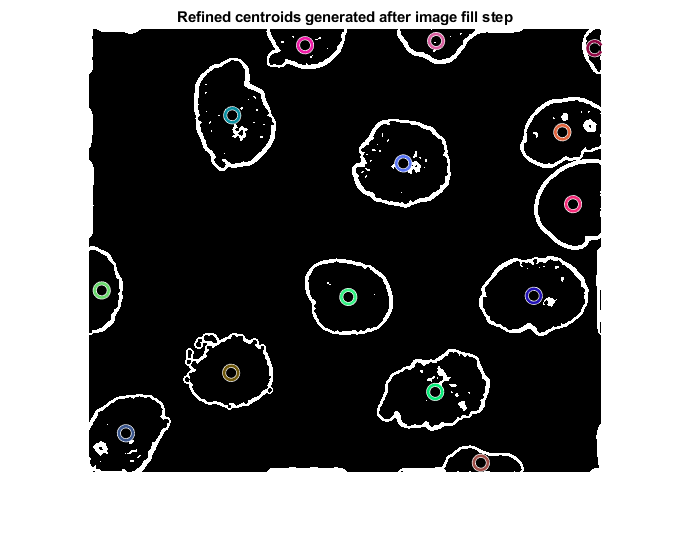

    90



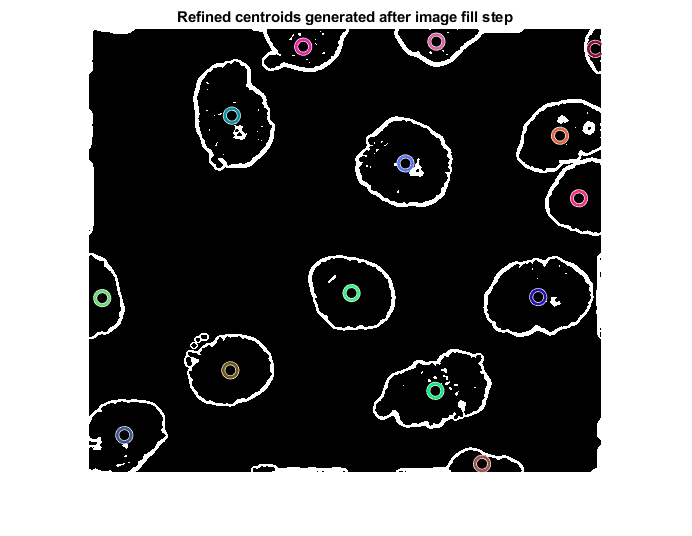

    91



Splitting event?


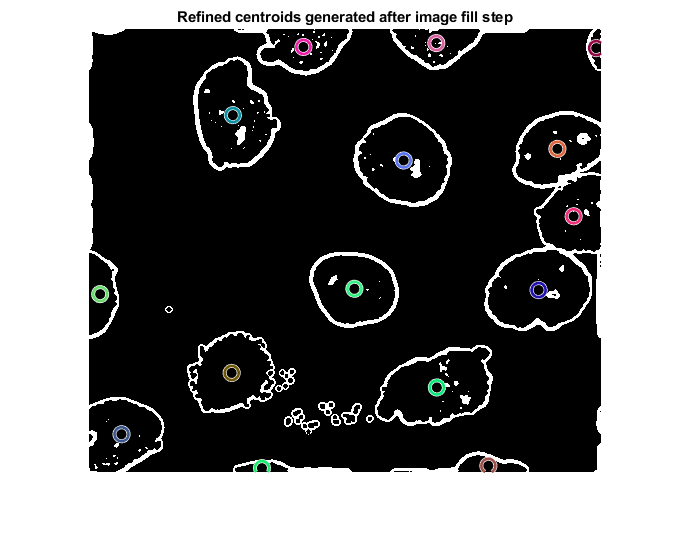

    92



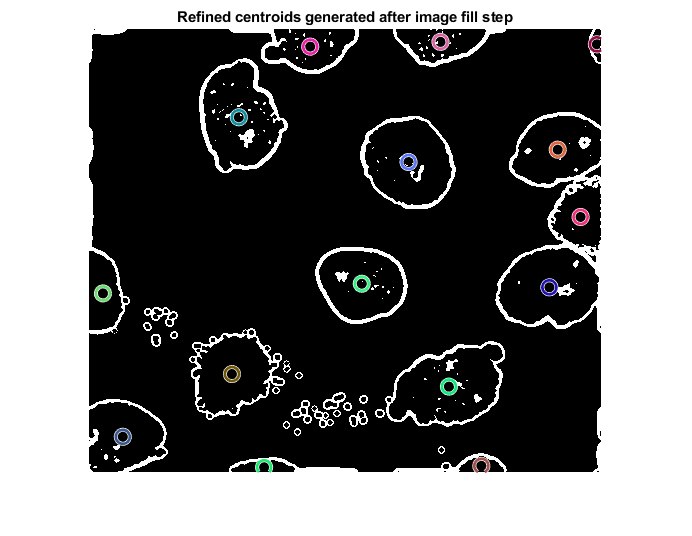

% Implementation of Phase Stretch Transform (PST) in Matlab
% Derived from work of: M. Asghari and Madhuri Suthar, Jalali Lab, Department of Electrical and Computer Engineering,  UCLA


%%Initial Setup 
clc  % clear screen
clear all  % clear all variables
close all   % close all figures
addpath('src/'); % script source directory

% New image loading
cell_dataset = cell_dataset('data/Fluo-N3DH-CHO/01/');
centroids_over_time = [];
curr_id = 0;
for time_slice = 1:size(cell_dataset, 4)
    disp(time_slice);
    % Work with a single 3D image for now
    Image_orig = cell_dataset(:,:,:, time_slice);
    
    % Repeat the Z axis by 5x, since the voxels are not even in X/Y/Z
    % Voxel size (microns): 0.202 x 0.202 x 1.0
    % Repeating Z axis by 5x should make the voxel size 0.202 x 0.202 x 0.2
    % (good enough)
    Image_orig = repelem(Image_orig, 1, 1, 5);
    
    %show the original image
    %subplot(1,2,1)
    %Image_orig = im2double(Image_orig(:,:,:));
    %imshow(Image_orig(:,:,1))
    %title('Original Image') % convert the grayscale image do a 2D double array
    
    %% Other edge detections
    % MK: Show edges using 1st order Sobel edge detector kernel
%     figure;
%     edge(Image_orig(:,:,6), 'sobel');
%     title('Original Image, Sobel edge detector');
%     figure;
%     edge(Image_orig(:,:,6), 'log');
%     title('Original Image, LoG edge detector');
%     figure;
    
    %% Noise Thresholding and Contrast
    %Thresholding and Clahe algo before pst contrast step to make cells more visible 
    for i = 1:size(Image_orig, 3)
        Image_orig(Image_orig<20)=2;
        %Image_orig = Image_orig * 1.05;
        %Image_orig(Image_orig<20)=2;
        
        Image_orig(:,:,i) = filter2(fspecial('average',2),Image_orig(:,:,i));
        
        Image_orig(:,:,i) = medfilt2(Image_orig(:,:,i));
        Image_orig(:,:,i) = adapthisteq(Image_orig(:,:,i), 'ClipLimit', 0.05);
        Image_orig(Image_orig<50)=2;
    end
    %UNCOMMENT for image
    %imshow(Image_orig(:,:,1))
    %title('Image Post Contrast')
    
    %% PST
    % low-pass filtering (also called localization) parameter
    handles.LPF=0.20; % Gaussian low-pass filter Full Width at Half Maximum (FWHM) (min:0 , max : 1)
    
    % PST parameters
    handles.Phase_strength=5;  % PST  kernel Phase Strength
    handles.Warp_strength=12.48;  % PST Kernel Warp Strength
    
    % Thresholding parameters (for post processing)
    handles.Thresh_min=-1;  % minimum Threshold  (a number between 0 and -1)
    handles.Thresh_max= 0.0019;  % maximum Threshold  (a number between 0 and 1)
    handles.Thresh_dark = 1/20; % dark threshold (between 0 and 1)
    
    [features, PST_Kernel] = PST_ND(Image_orig, handles);
    [edge] = PST_post(Image_orig, features, handles);
    
    
    % MK: Best edges on Z layer 21
    refined_edge = edge(:,:,21:25);
    
    % Show and save 'analog' edge output
    filename = 't000.tif';
    %figure;
    features_img = [];
    for i = 1:size(features, 3)
        features_img(:,:,i) = features(:,:,i)/max(features(:,:,i), [], 'all')*3;
    end
    %features_img = features(:,:,1)/max(features, [], 'all')*3;
    
    % Post proccess features_img
    edge(edge < 0) = 0;
    features_img(features_img > 0.005) = 1;
    
    %UNCOMMENT for image
    %imshow(features_img(:,:,1))
    %title('Detected features using PST')
    %file_and_extension = strsplit(filename,'.');
    %output_path = char(strcat('data/Test_Images/',file_and_extension(1),'_features.tif'));
    %imwrite(features_img(:,:,1), output_path);
    
    %%Centroid Detection via DoG
    
    %Convert image to binary blobs
     
    scale_space = dog3(features_img, [10, 15, 20, 25]);
    thresh = 0.5; % Tune so there is one blob per cell
    scale_space(scale_space < thresh) = 0;
    scale_space(scale_space >= thresh) = 1;
    
    %Centroid Detection
    start_cents = [];
    for j = 1:size(scale_space, 4)
        cc = bwconncomp(scale_space(:,:,:,j), 18);
        stats = regionprops(cc, 'Centroid');
        for i = 1:size(stats, 1)
            start_cents = [start_cents ; stats(i).Centroid];
        end
    end
    
    %TODO: Wrap centroids in a data type so no need to deal with different
    %sized arrays (changes in number of centroids)
    
    %centroids_over_time(:,:, time_slice) = start_cents;
    
    % Show Centroids on PST
    %UNCOMMENT for image
    %figure;
    %imshow(features_img(:,:,1));
    %radii = ones(size(start_cents, 1), 1) * 1;
    %viscircles(start_cents(:,[1,2]), radii);
    %title('Detected Centroids')
    % save the image
    %file_and_extension=strsplit(filename,'.');
    %output_path=char(strcat('data/Test_Images/',file_and_extension(1),'_edge.tif'));
    %imwrite(features_img(:,:,1), output_path);
    
    % Try to fill in the cells with imfill. Discard fills that are very
    % small or very large and generate, per fill, the number of pixels
    % filled and the mean of those points
    refined_centroids = [];
    cell_sizes_px = [];
    BW1 = features_img(:,:,1) > 0;
    for i = 1:size(start_cents, 1)
        
        % Binarize the 2D image then fill from the starting centroid. Use
        % the imfill() documentation variable names for clarity
        BW2 = imfill(BW1, round(start_cents(i, [2,1]))); % start_cents seems to have backwards indexing?
        BWdiff = BW2 - BW1;
        
        % Generate the number of pixels changed and, if reasonable, add to
        % the list
        min_pixels_changed = 100; % Chosen at random, tweak if we have trouble detecting small cells
        max_pixels_changed = numel(BW1) / 2; % No cell is taking up half the image
        [rpoints, cpoints] = find(BWdiff); % Diff images and get row/col points
        if (length(rpoints) < min_pixels_changed || length(rpoints) > max_pixels_changed)
            continue; % Something funky is going on, skip this fill
        end
        BW1 = BW2; % Use the filled image here, so we don't re-fill cells for duplicate centroids
        
        % Looks good, find its center and add it to the list
        refined_centroids = [refined_centroids; [mean(rpoints), mean(cpoints)]];
        cell_sizes_px = [cell_sizes_px; length(rpoints)];
    end
    
    %Add track centroids.  
    %TODO: doesn't take into account splits or new centroids drifting in,
    %need to add that (minimum distance check, approx equal dist check)
    
    %If first, just save all the centroids
    if time_slice == 1
        cents = CellCentroids([])
        for i = 1:size(refined_centroids, 1)
            cell = Cell(refined_centroids(i, :), i, [rand, rand, rand], cell_sizes_px(i));
            cents = CellCentroids([cents.Cells; cell]);
        end
        centroids_over_time = [centroids_over_time ; cents];
        curr_id = size(refined_centroids, 1);
    else
        %Compare to previous set of centroids
        cents = centroids_over_time(time_slice-1);
        new_cents = CellCentroids([]);
        already_id = [];
        %For every refined_centroid, find the closest known centroid
        for i = 1:size(refined_centroids, 1)
            best_score = 99999;
            id = -1;
            id_color = [];
            found = 0;
            for j = 1:size(cents.Cells, 1)
                known_cent = cents.Cells(j).Centroid;
                known_label = cents.Cells(j).Label;
                known_area = cents.Cells(j).Area;
                
                search_cent = refined_centroids(i, :);
                %Deltas for distance and area
                delta = sqrt((known_cent(1, 1) - search_cent(1, 1))^2 + (known_cent(1,2)-search_cent(1,2))^2);
                area_delta = abs(known_area - cell_sizes_px(i))/max(known_area, cell_sizes_px(i)) * 100;
                %Calculate total score
                score = delta*1 + area_delta;
                %Calculate the distance threshold
                distance_threshold = sqrt(cell_sizes_px(i)/pi) * 2;
                %If our score is the best one we've seen, our distance is
                %less than the threshold and we haven't used this cell
                %previously, update best cell
                if score < best_score && delta < distance_threshold && ~any(already_id(:) == known_label)
                    best_score = score;
                    id = known_label;
                    id_color = cents.Cells(j).Color;
                    found = 1;
                end
            end
            %If we found the best cell as the tracked target, add to list
            %of tracked.  
            if found == 1
                already_id = [already_id id];
                cell = Cell(refined_centroids(i, :), id, id_color, cell_sizes_px(i));
                new_cents = CellCentroids([new_cents.Cells; cell]);
            %Otherwise, couldn't find the cell.  
            %TODO: Do this better.  Right now, if it doesn't find the cell,
            %it just assumes its a new one - maybe not best way.  
            else
                if size(refined_centroids, 1) > size(cents.Cells, 1)
                    disp("Splitting event?")
                end
                curr_id = curr_id + 1;
                cell = Cell(refined_centroids(i, :), curr_id, [rand, rand, rand], cell_sizes_px(i));
                new_cents = CellCentroids([new_cents.Cells; cell]);
            end
        end
        centroids_over_time = [centroids_over_time ; new_cents];
    end
    
    % Plot it with the updated centroids
    f = figure;
    imshow(features_img(:,:,1) > 0);
    
    viscircles(refined_centroids(:,[2,1]), 7*ones(length(refined_centroids),1));
    for i = 1:size(centroids_over_time(time_slice).Cells, 1)
        viscircles(centroids_over_time(time_slice).Cells(i).Centroid([2,1]), 7, 'Color', centroids_over_time(time_slice).Cells(i).Color);
    end
    %viscircles(refined_centroids(:,[2,1]), 7*ones(length(refined_centroids),1));
    title("Refined centroids generated after image fill step");
    frame = getframe(f);
    im = frame2im(frame);
    [A,map] = rgb2ind(im,256);
    if time_slice == 1
        imwrite(A, map,'cell_track.gif','gif','LoopCount',Inf,'DelayTime',0.2);
    else
        imwrite(A, map,'cell_track.gif','gif','WriteMode','append','DelayTime',0.2);
    end

    %UNCOMMENT for image
    % overlay original image with detected features
    %overlay = imoverlay(Image_orig, features_img(:,:,1), [1 0 0]);
    %figure;
    %imshow(overlay/max(overlay, [], 'all'));
    %imshow(overlay);
    %title('Detected features using PST overlaid with original image')
    % save the image
    %output_path=char(strcat('data/Test_Images/',file_and_extension(1),'_overlay.tif'));
    %imwrite(overlay/max(overlay, [], 'all'), output_path);
    
    % show the PST phase kernel gradient
    %UNCOMMENT for image
    %figure;
    %[D_PST_Kernel_x, D_PST_Kernel_y, D_PST_Kernel_z]=gradient(PST_Kernel);
    %mesh(sqrt(D_PST_Kernel_x(:,:,1).^2+D_PST_Kernel_y(:,:,1).^2+D_PST_Kernel_z(:,:,1).^2));
    %title('PST Kernel phase Gradient');
end